# Estimating Clients' Needs

## How to use this live script

In this executable notebook (Live Editor) you have a logical track of the work, with working code snippets, some (non-binding) method suggestions.

Always remember: when it comes to data modeling, there is almost never a "one size fits all", thus you can take various ways to solve the problem.

So feel free to take this code as a draft, change it, even significantly, following your modeling vision. Feel free to explore data and methods and gain experience (yes, even getting it wrong and getting results you don't like - it's quite normal in real applications). You will find some "*HINTS*": they are just suggestions for you. Remember: experimenting with data - that's the purpose of this Machine Learning Lab.

## Goal: Recommendation System/Next Best Action

Here we have a random extraction of a dataset made up of a wealth manager's customers. The data is anonymous, mostly clean and NOT always normalized/scaled.

We intend to estimate some **investments needs **for these customers using Data Science techniques.

Estimating needs is useful for many reasons, for example:

- as a basis for a **Recommender System, i.e. finding the "Next Best Action"** - basically needs can be the key inputs of content-based/knowledge-based filtering algorithms - this is our key task here;

- **product targeting/governance** (also from the compliance point of view) as MIFID/IDD standards require a matching between customer needs and needs satisfied by the product - but is basically an institutional view of a recommendation system.

The dataset is called "Needs" and is conveniently saved as a .mat file, even if you have also the corresponding .xls file.

In the dataset we have a table **Needs**, with some (maybe) relevant features and two responses:

- AccumulationInvest, which is about **Accumulation investing**, typically using dollar-cost averaging (you invest small amounts of your money at certain intervals over the course of time); the response is boolean: 1 = high propensity | 0 = low propensity;

- IncomeInvest, which is about **Income investing**, typically through lump sum investing (one shot); the response is boolean: 1 = high propensity | 0 = low propensity.

Then we have a second table, **Products**, with some products (funds, segregated accounts, unit-linked), their **type** (1 = Accumulation, 0 = Income), and their **risk level** (normalized in the range [0,1], usually; this is the synthetic risk and reward indicator or SRRI, for the product).

The recommendation system is based on two key steps

- We want to learn to recognize customers with above-average propensity to invest (AccumulationInvest = 1, and/or IncomeInvest = 1);

- For each customer we will associate a product with each need, finding the best match, based on the product type/need and its risk level, and that will be the personalized product recommendation, ie, the Next Best Action for that specific client.

#### *Load data*

close all
clc
load('Needs.mat')

## Quick data exploration

We start looking at univariate distributions. For example, we check for imbalanced classes

Data = Needs; % renaming (we'll likely manipulate this matrix, but we don't touch the original matrix)

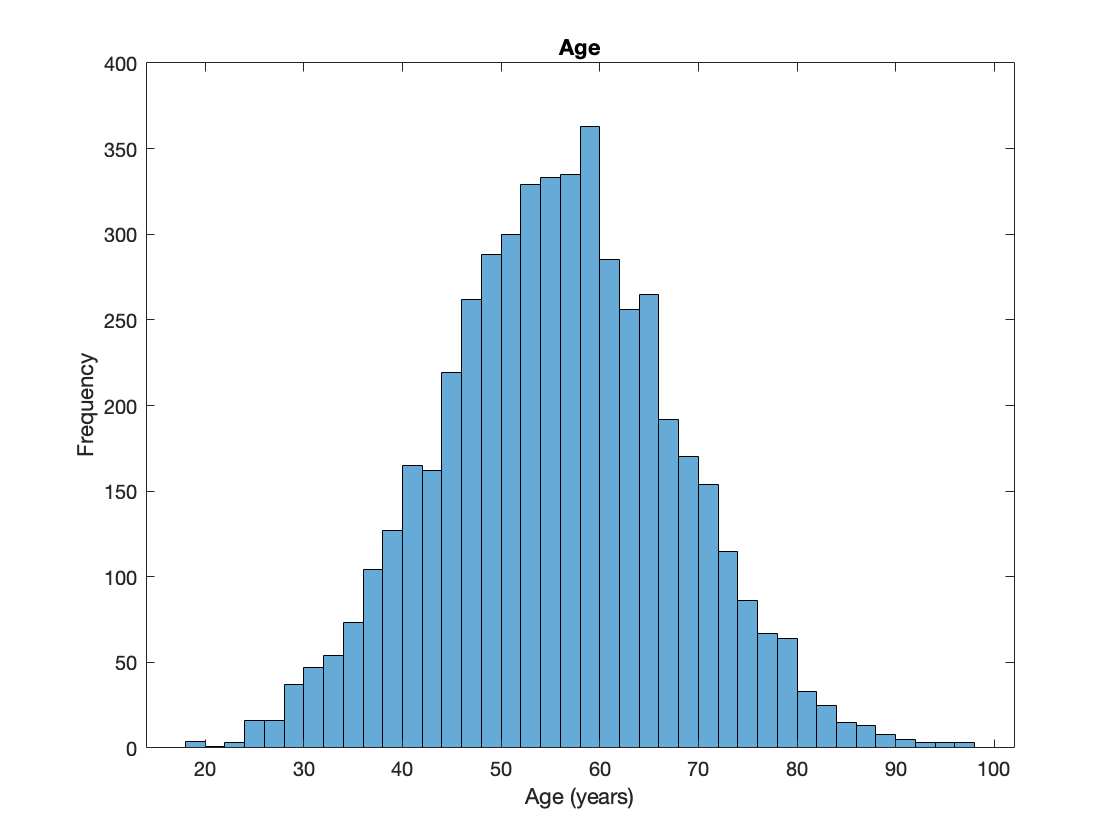


figure
histogram(Data.Age)
title('Age')
xlabel('Age (years)')
ylabel('Frequency')

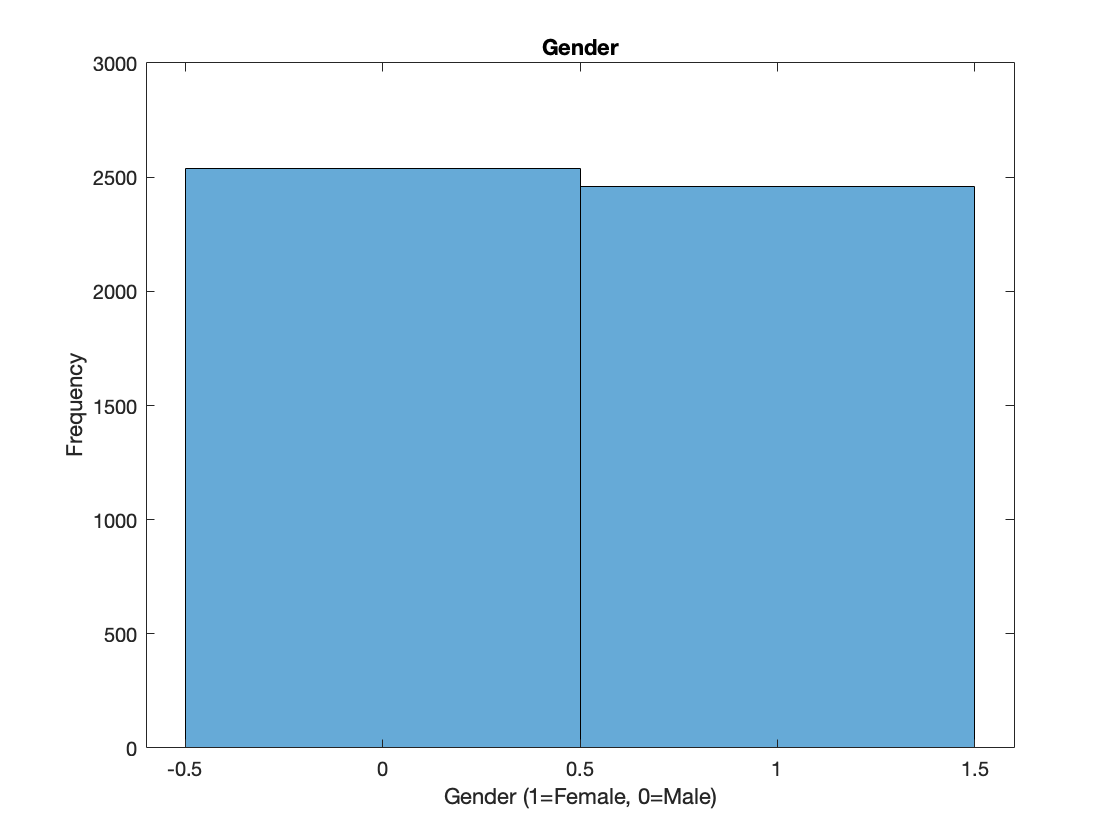

figure
histogram(Data.Gender)
title('Gender')
xlabel('Gender (1=Female, 0=Male)')
ylabel('Frequency')

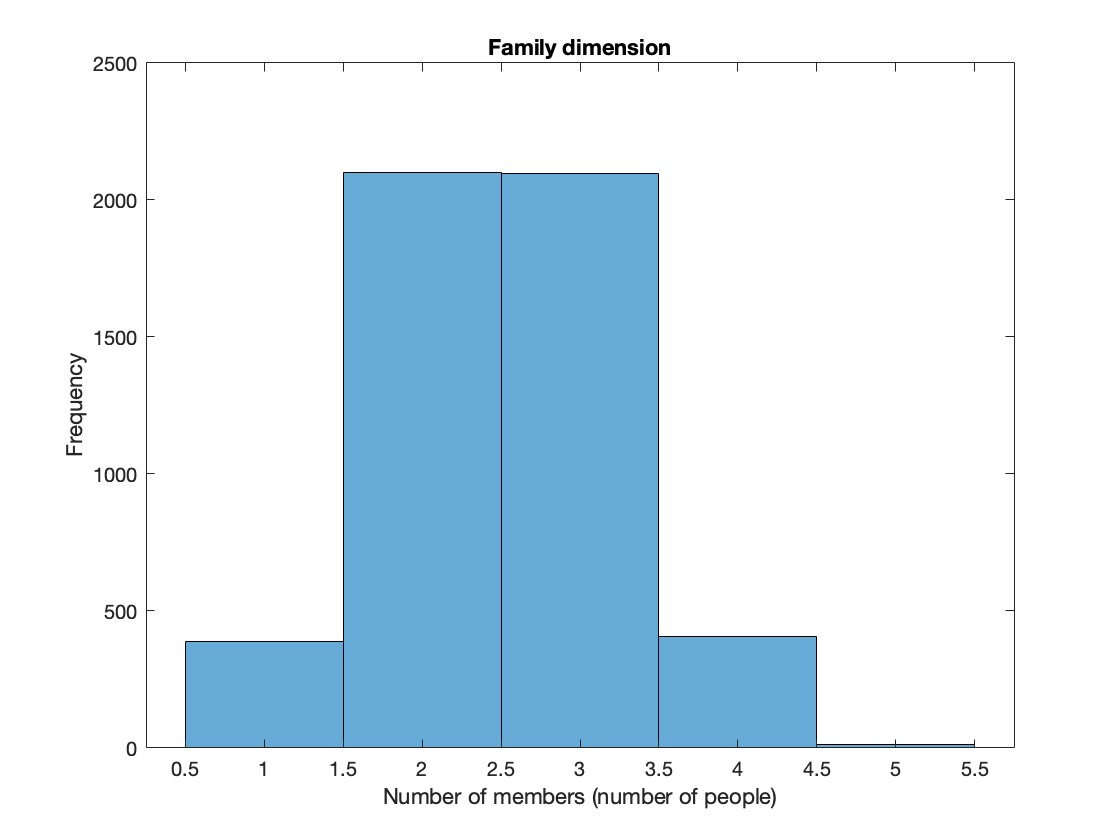

figure
histogram(Data.FamilyMembers)
title('Family dimension')
xlabel('Number of members (number of people)')
ylabel('Frequency')

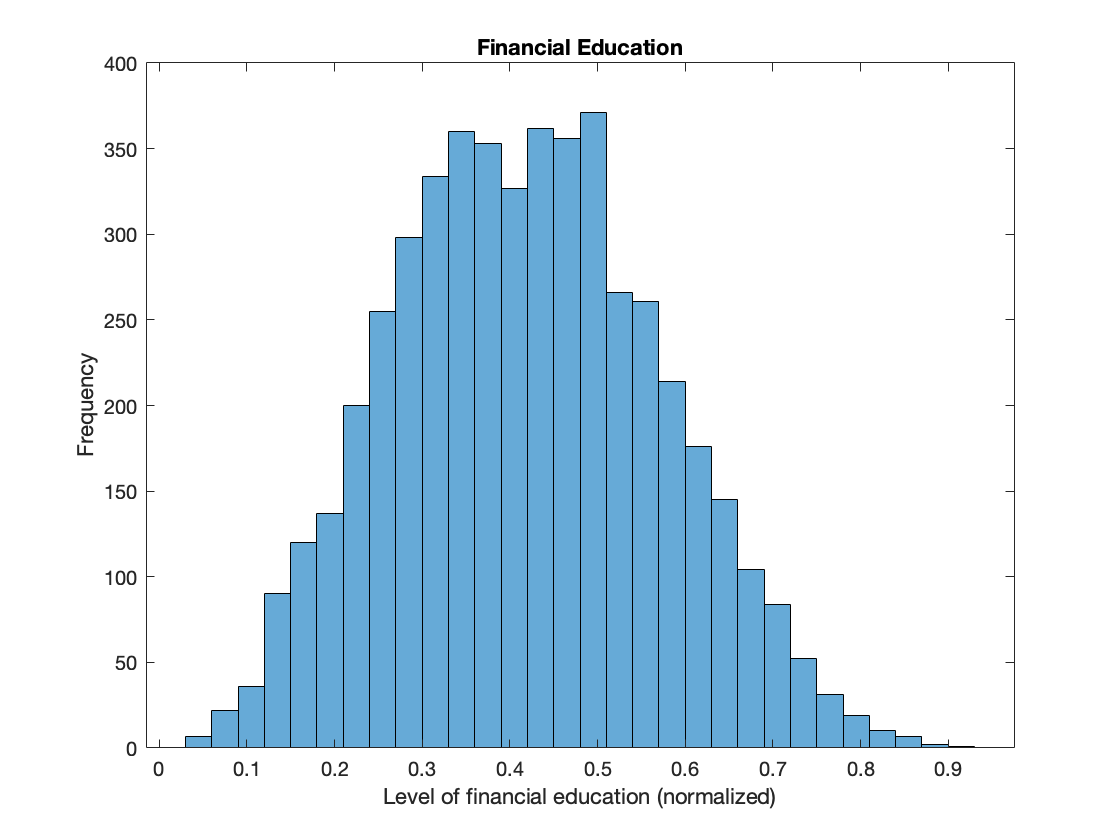

figure
histogram(Data.FinancialEducation)
title('Financial Education')
xlabel('Level of financial education (normalized)')
ylabel('Frequency')

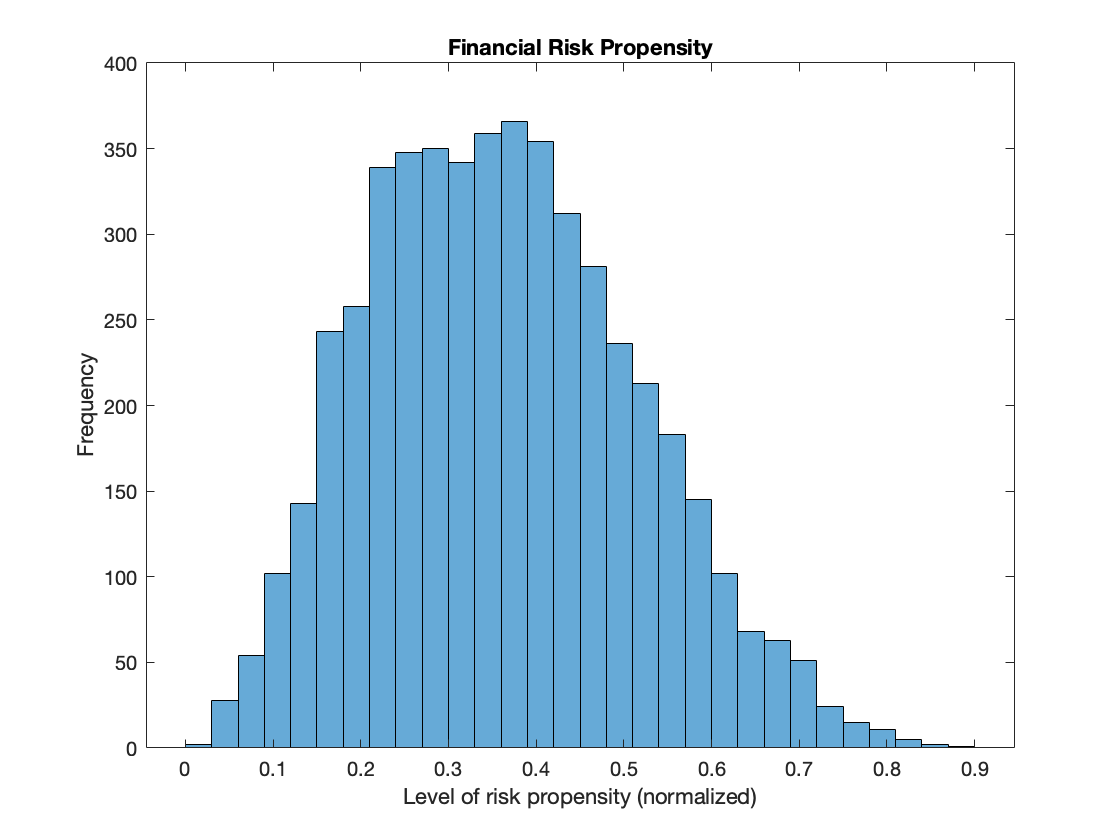

figure
histogram(Data.RiskPropensity)
title('Financial Risk Propensity')
xlabel('Level of risk propensity (normalized)')
ylabel('Frequency')

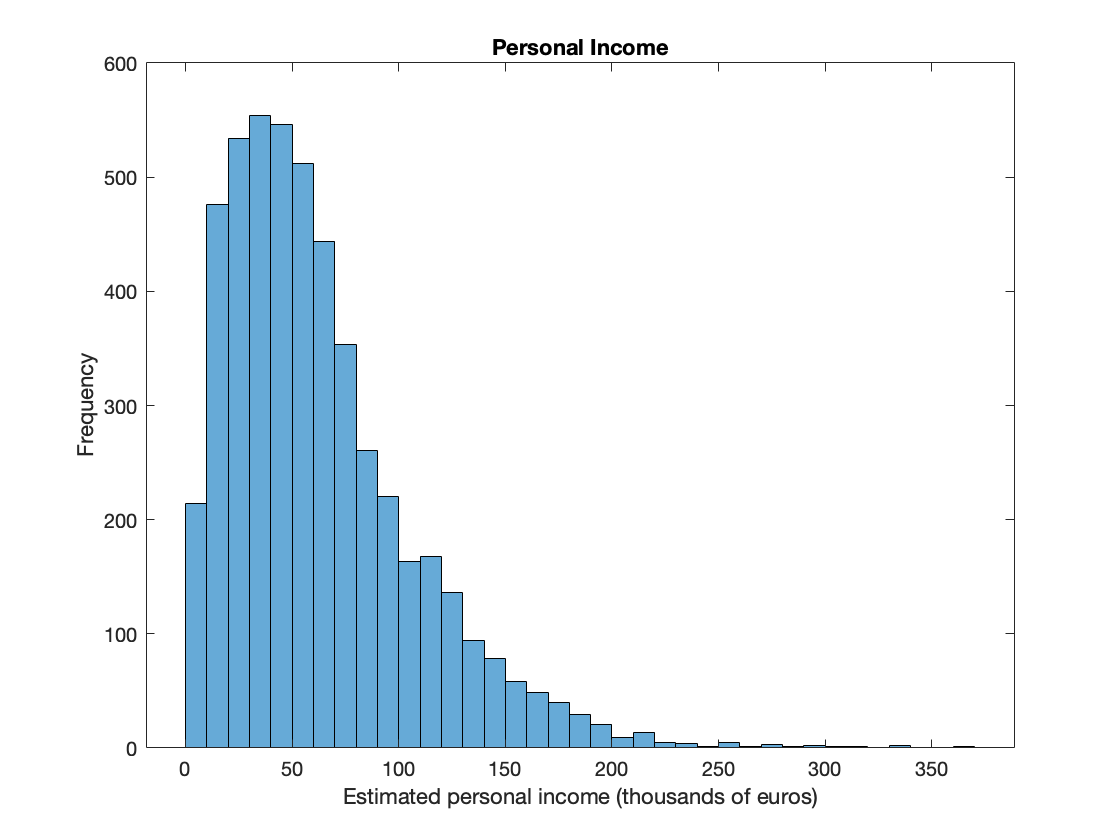


figure
histogram(Data.Income)
title('Personal Income')
xlabel('Estimated personal income (thousands of euros)')
ylabel('Frequency')

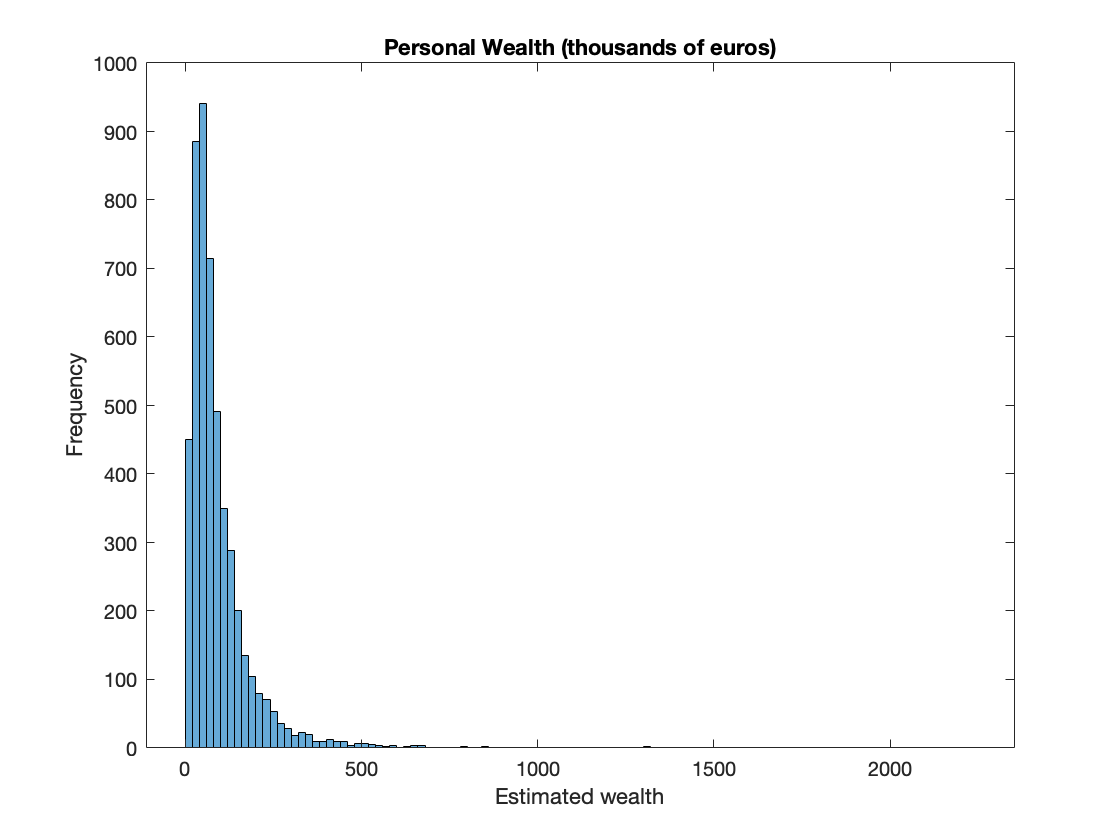

figure
histogram(Data.Wealth)
title('Personal Wealth (thousands of euros)')
xlabel('Estimated wealth')
ylabel('Frequency')

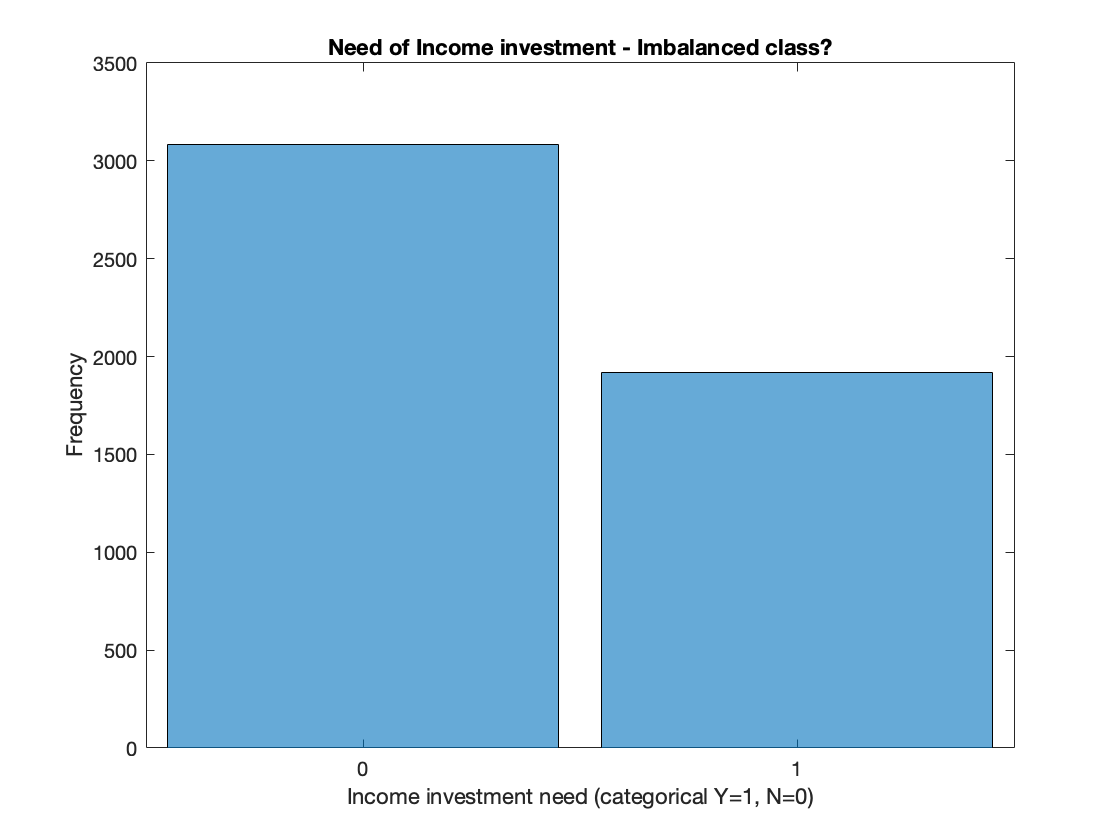

figure
histogram(Data.IncomeInvestment)
title('Need of Income investment - Imbalanced class?')
xlabel('Income investment need (categorical Y=1, N=0)')
ylabel('Frequency')

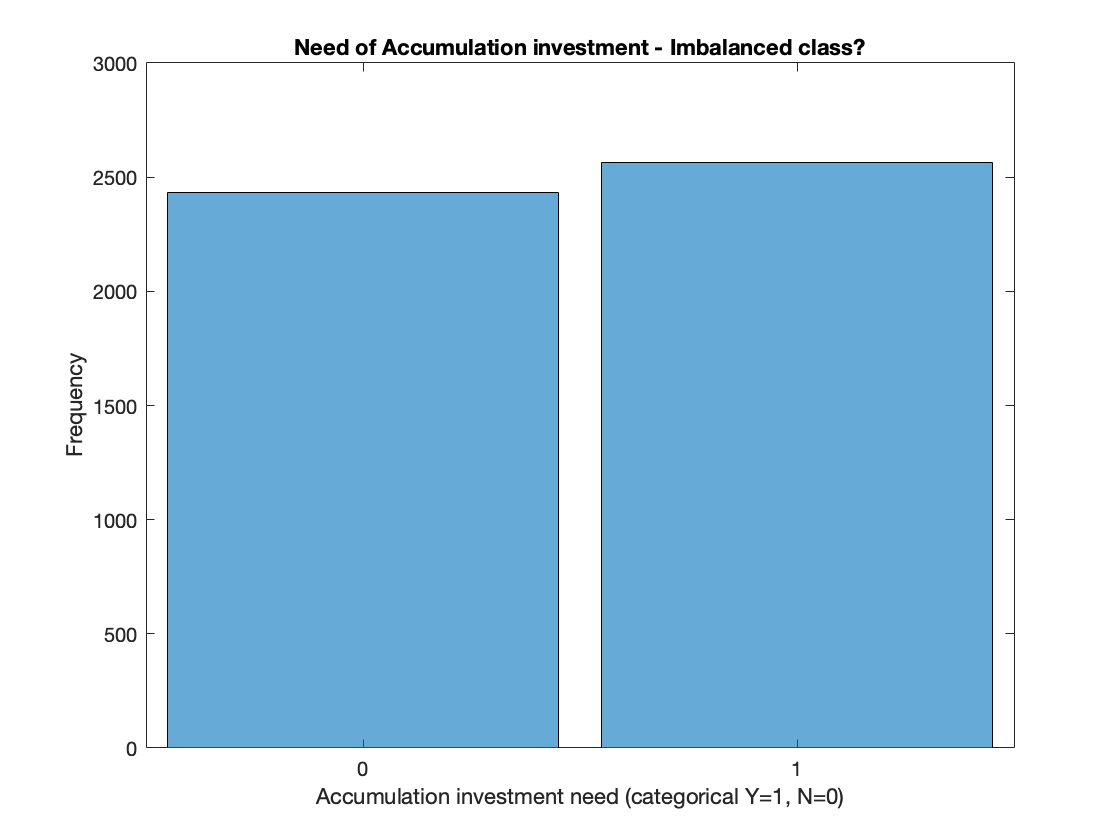

figure
histogram(Data.AccumulationInvestment)
title('Need of Accumulation investment - Imbalanced class?')
xlabel('Accumulation investment need (categorical Y=1, N=0)')
ylabel('Frequency')

# Heatmaps

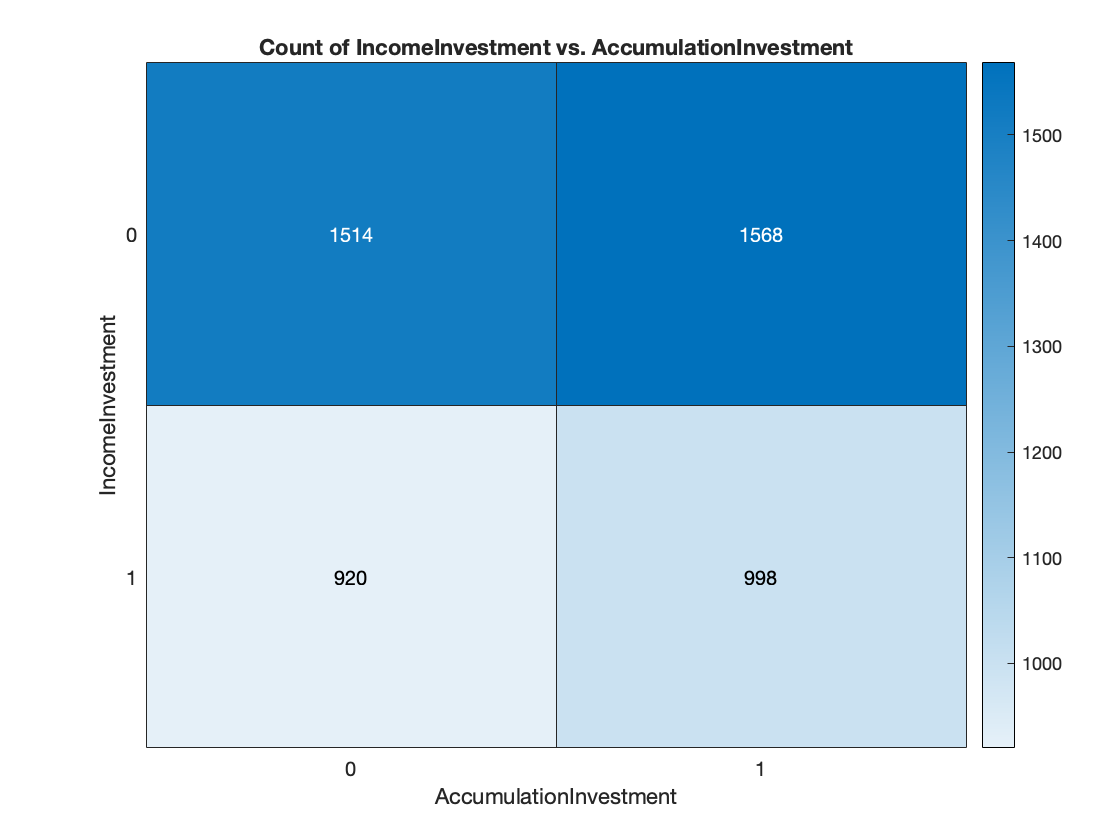

heatmap(Data, "AccumulationInvestment", "IncomeInvestment")

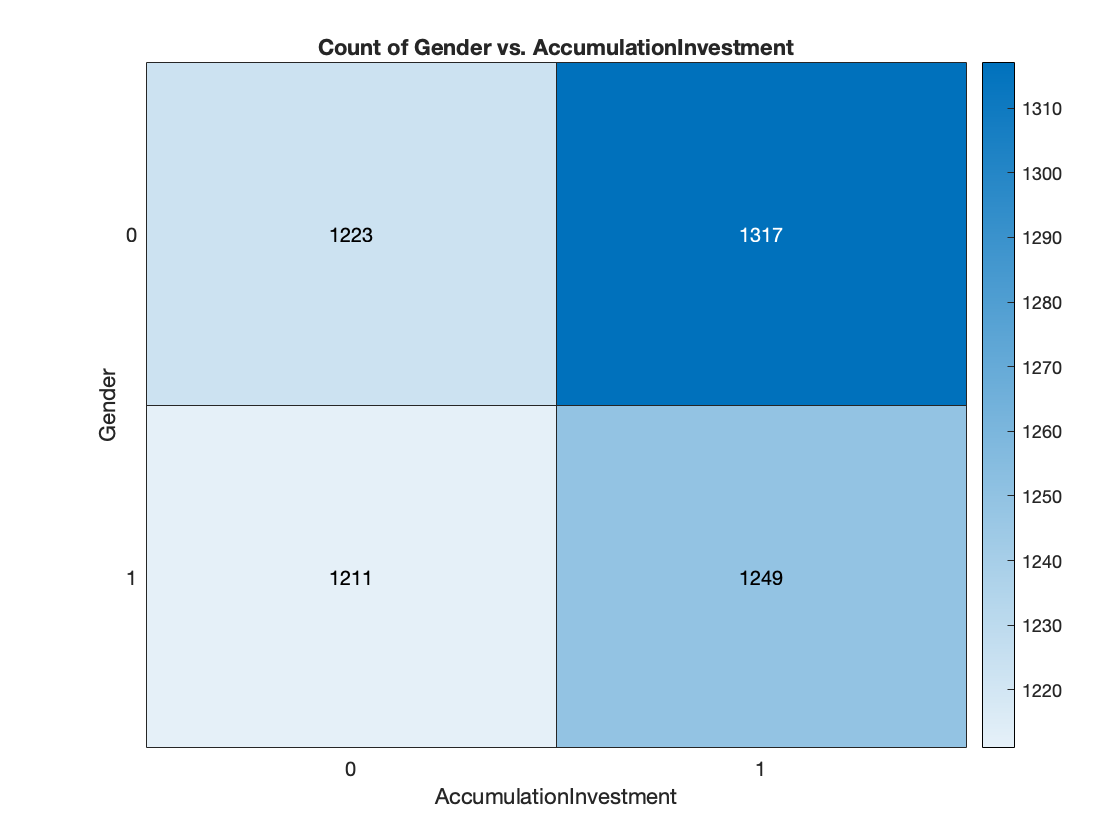

heatmap(Data, "AccumulationInvestment","Gender")

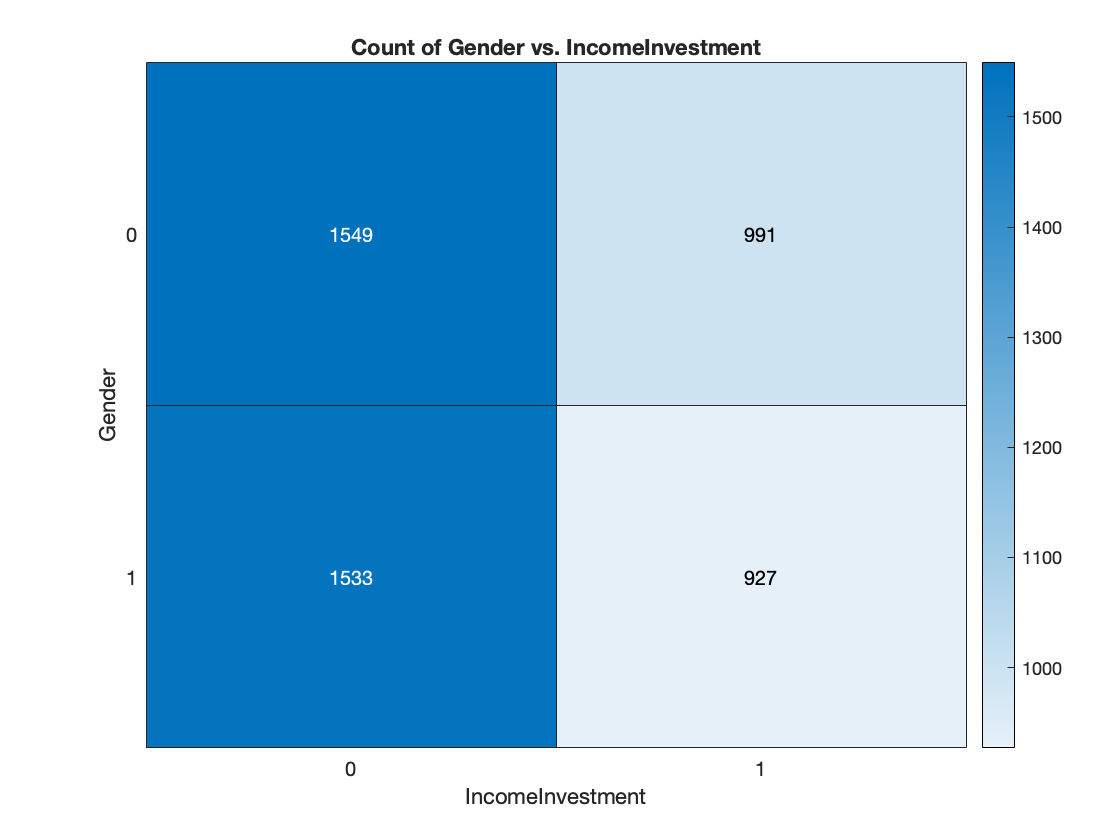

heatmap(Data, "IncomeInvestment", "Gender")

### Data transformation

Wealth and Income follow a power law, so it's better to apply some transformation rule (e.g., log transformation, power transformation).

*HINT*: try some other transformations.

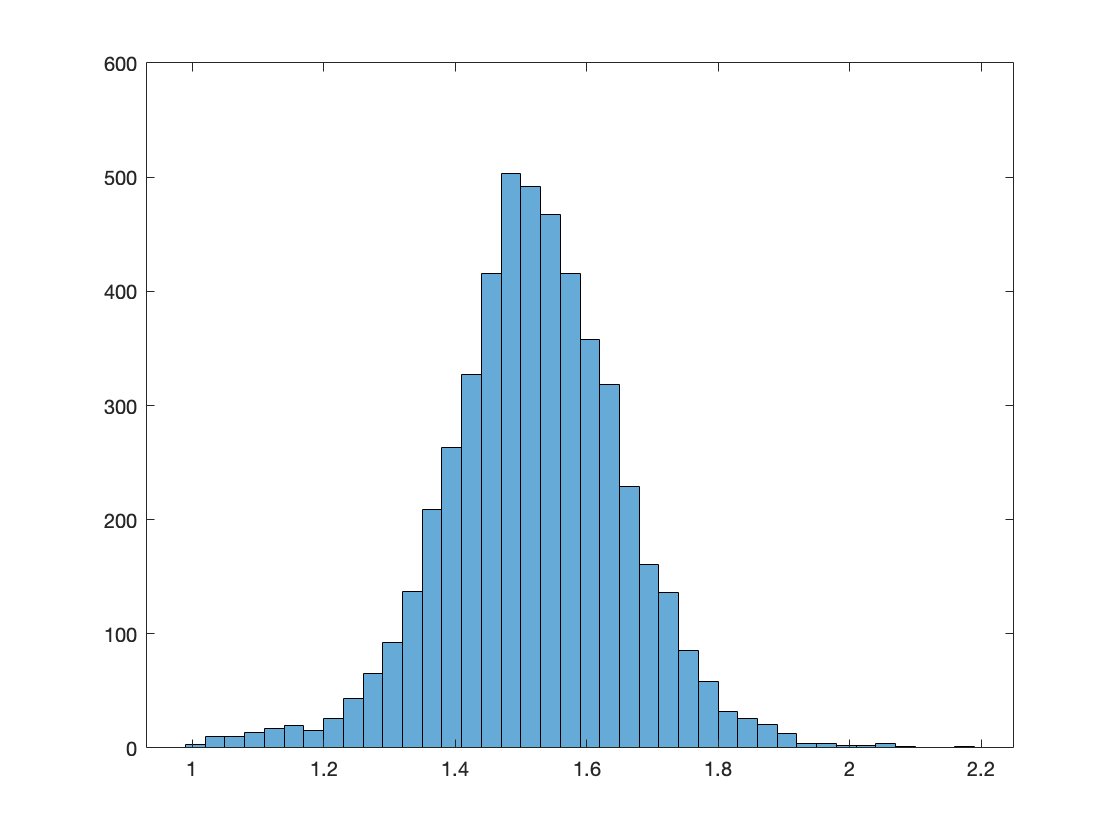

p = 0.1;
histogram(Data.Wealth.^p); % power transformation

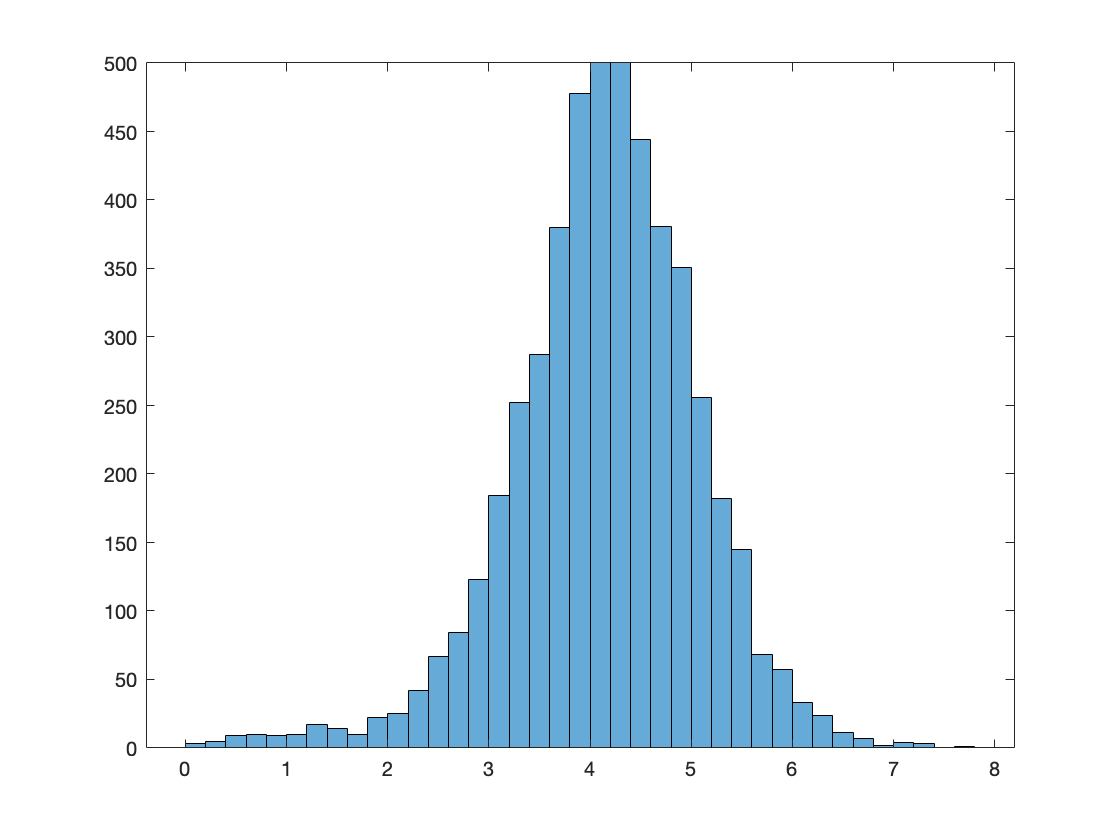

histogram(log(Data.Wealth)) % log transformation

% for i = 1:5
%     baseD = randsample(Data.Wealth,800);
%     for p = 0.1:0.1:0.2
%         disp(p)
%         testi = baseD.^(p);
%         result = normalitytest(testi');
%    end
% end
% not ci sono abbastanza evienze

%logWealth = log(Data.Wealth); % we'll go for the log-transformation
pWealth = Data.Wealth.^(0.1);   % we'll go for the 0.1-transformation

% baseD = randsample(logWealth,800);
% Result = normalitytest(baseD');

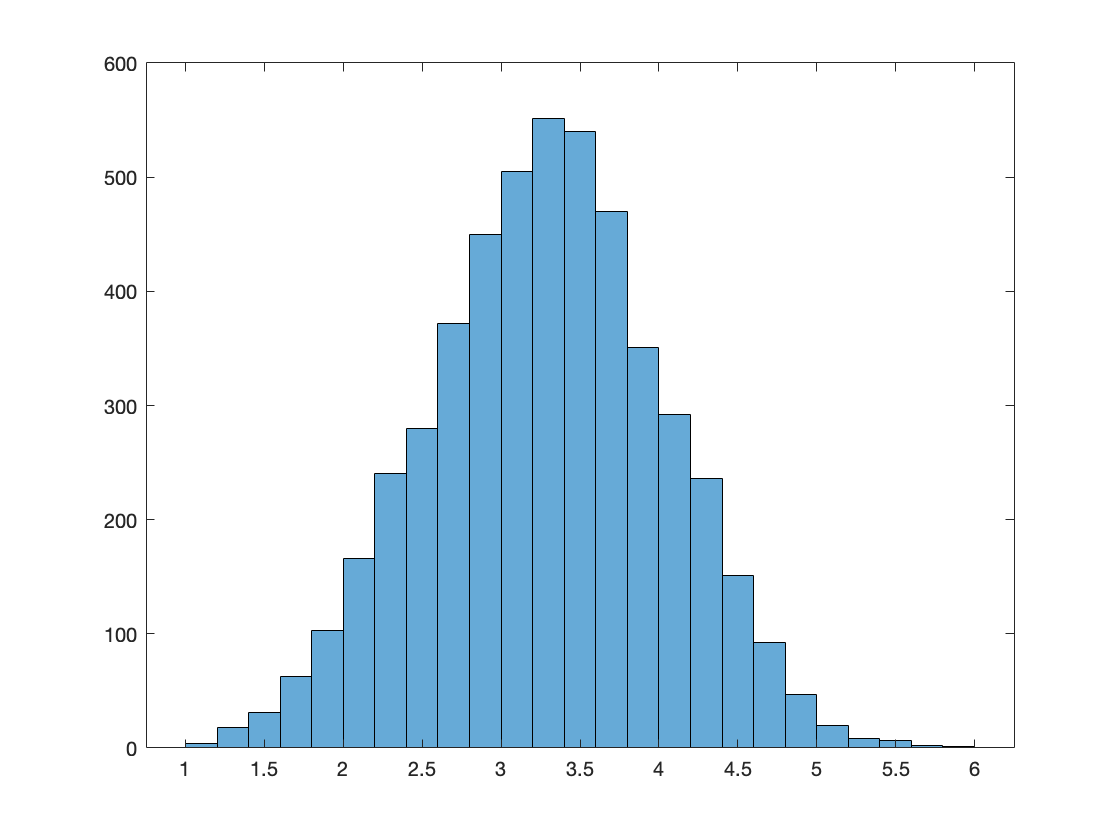

p = 0.3;
histogram(Data.Income.^p); % power transformation

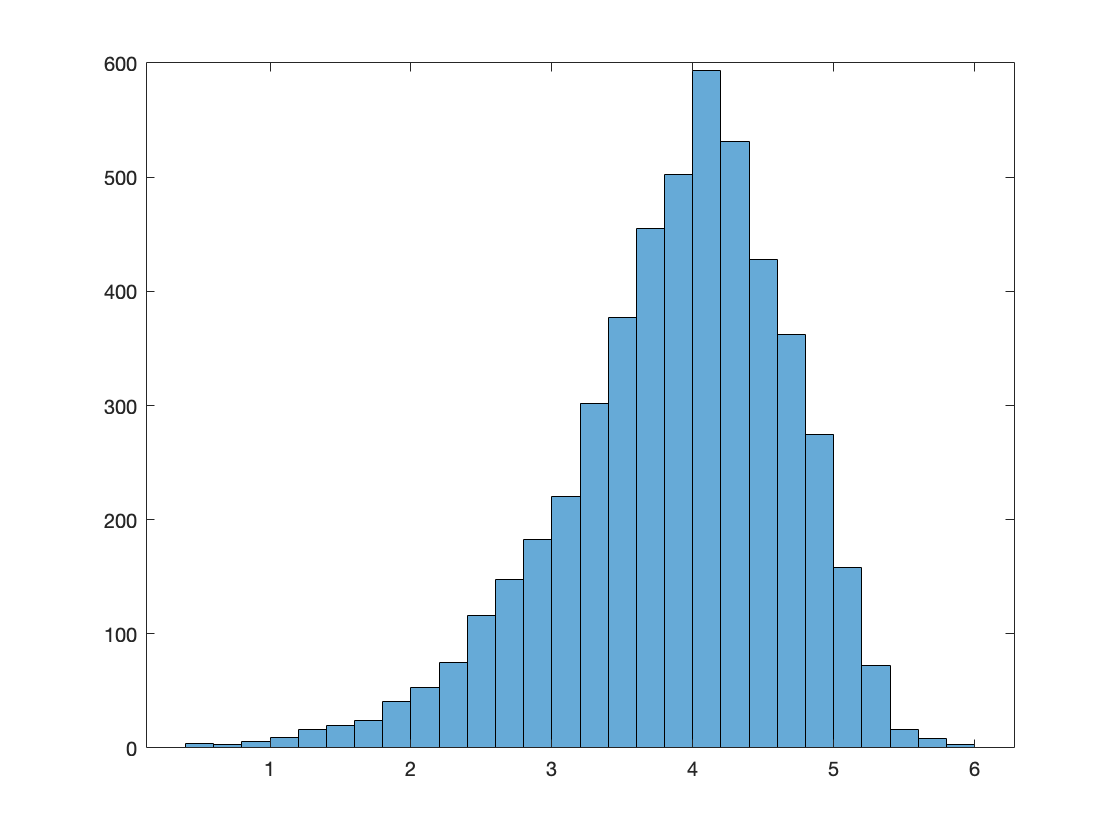

histogram(log(Data.Income)) % log transformation

% for i = 1:5
%     baseD = randsample(Data.Income,800);
%     for p = 0.3:0.1:0.4
%         disp(p)
%         testi = baseD.^(p);
%         result = normalitytest(testi');
%     end
% end
% p = 0.3 best result

% logIncome = log(Data.Income); % we'll go for the log transformation
pIncome = Data.Income.^(0.3);

boxAge = Data.Age;
[TRANSDAT, LAMBDA] = boxcox(boxAge);

pAge = Data.Age.^(0.9);


boxFin = Data.FinancialEducation;
[TRANSDAT, LAMBDA] = boxcox(boxFin);

pFin = Data.FinancialEducation.^(0.8);

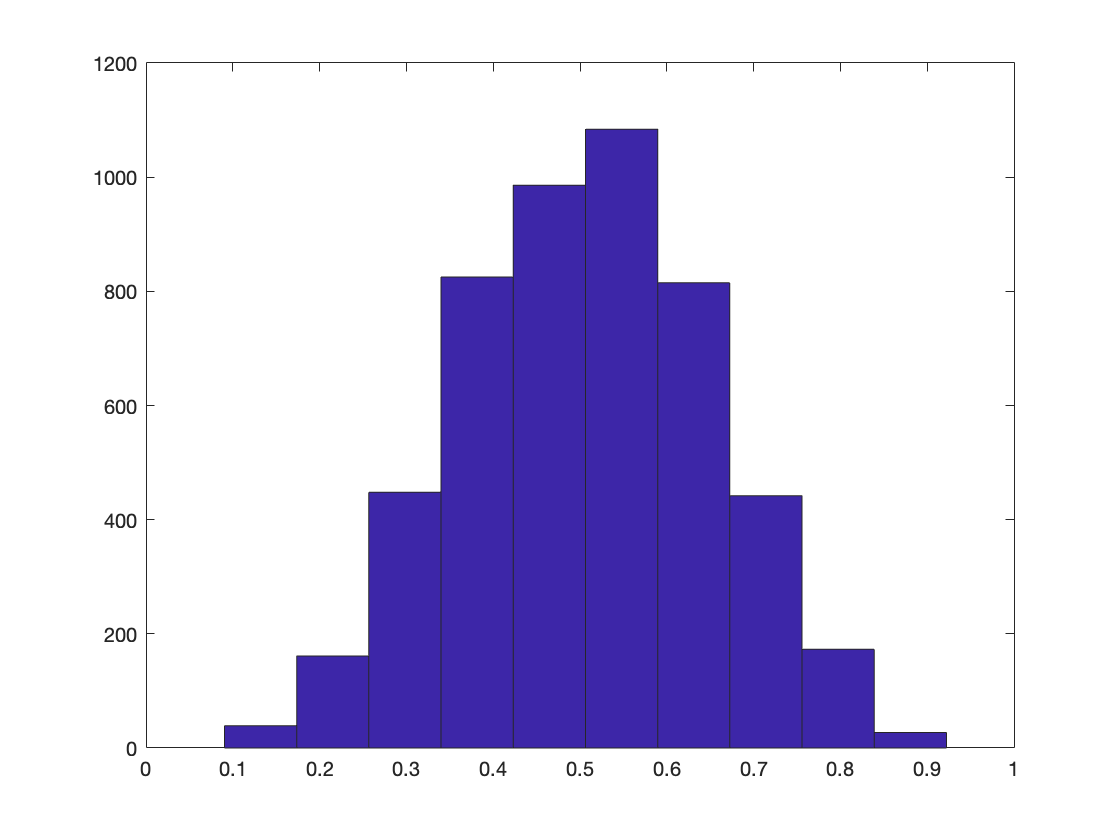

boxRisk = Data.RiskPropensity;
[TRANSDAT, LAMBDA] = boxcox(boxRisk);

pRisk = Data.RiskPropensity.^(0.65);
hist(pRisk)

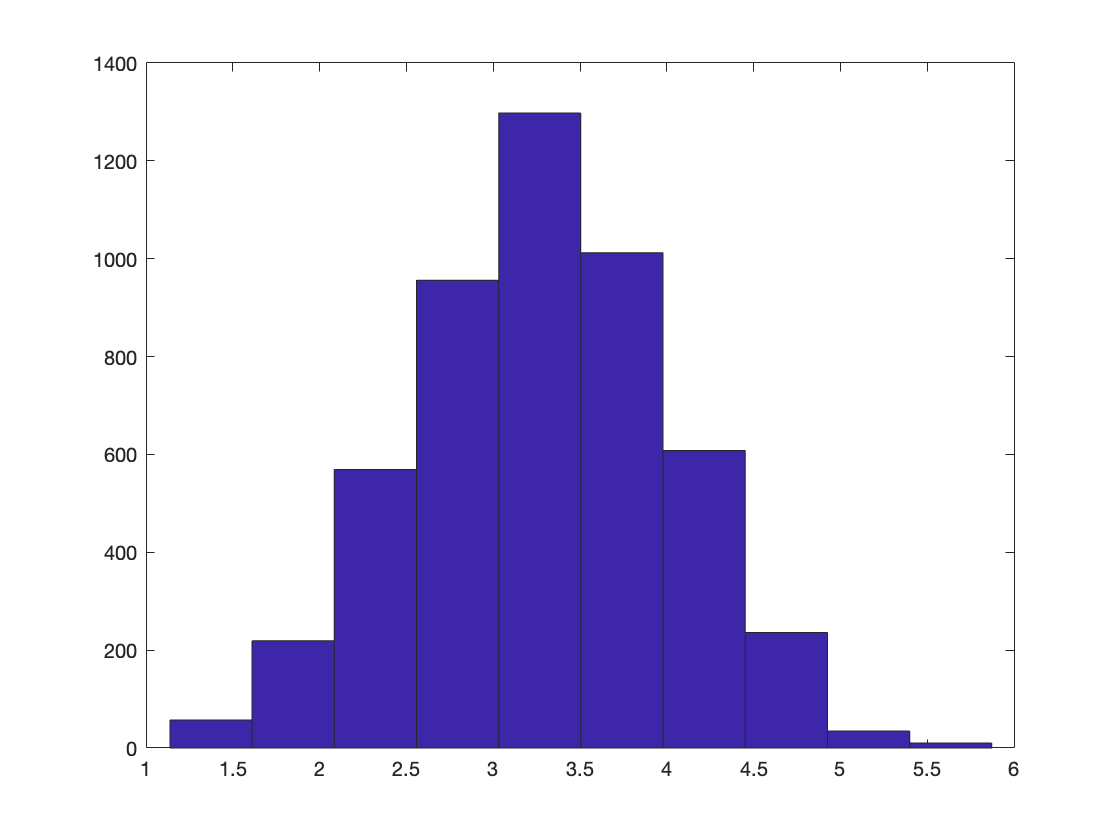

boxInc = Data.Income;
[TRANSDAT, LAMBDA] = boxcox(boxInc);

pIncome = Data.Income.^(0.3);

Now, let's  keep pre-processing our data, checking how scaling and normalization (min/max normalization) affect our data. When you have to measure the distances between pairs of samples, those distances will be influenced by the measurement units used - for example if you use k-NN - normalizing is key. Otherwise it can be less important, as long as the orders of magnitude are the same; so in practice if one variable is in [-1, 2], the other in [0, 4], or [-2, 2], etc, typically is OK.

Consider also that both normalization and scaling are affine transformations (i.e. a+b*x), so they change just the location parameter (i.e. the mean) and the scale parameter (i.e. the standard deviation), NOT the shape of the probability distribution.

*HINT*: in practice, when using a model, try various different pre-processings of the data, without scaling, min/max scaling, z-score, scaling dividing by the sum of absolute values of your data (which would make it to lie on a simplex), etc. This thing is often opaque, as you are (likely) not so sure about the next move, so this video from Andrew NG can be of help: [https://www.youtube.com/watch?v=FDCfw-YqWTE](https://www.youtube.com/watch?v=FDCfw-YqWTE)

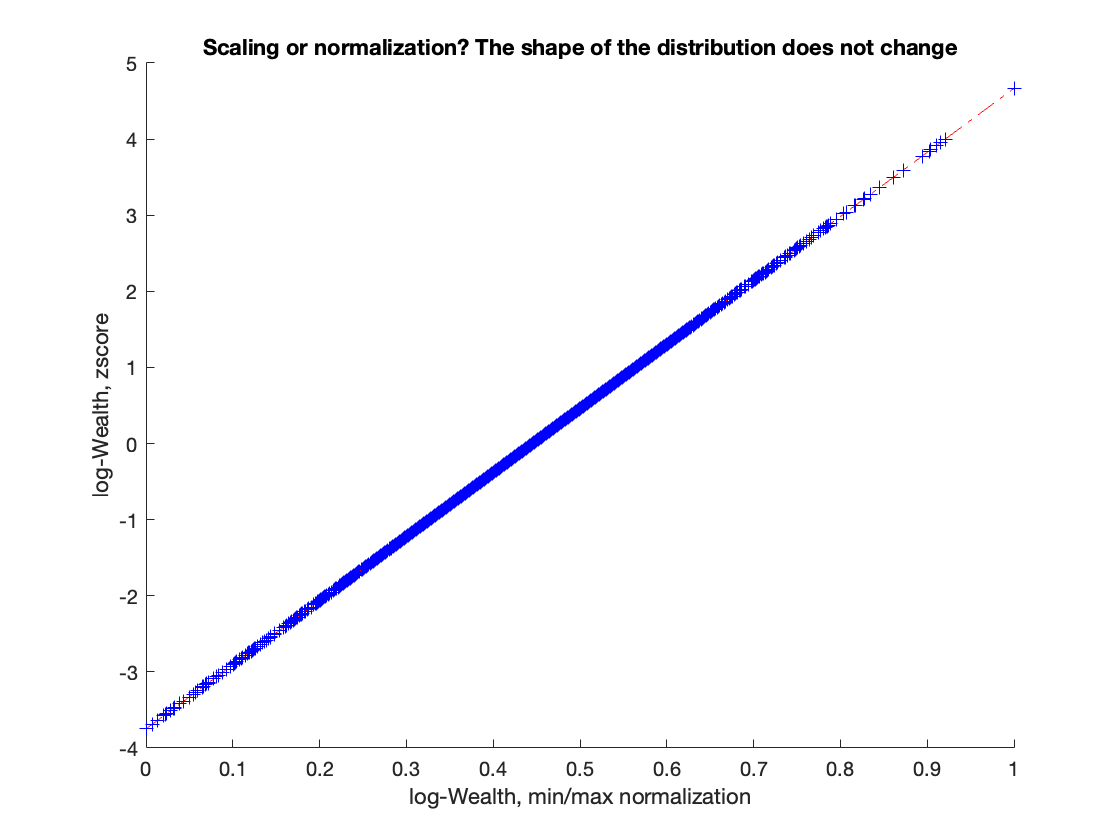

% qqplot(rescale(logWealth), zscore(logWealth))
qqplot(rescale(pWealth), zscore(pWealth))
title('Scaling or normalization? The shape of the distribution does not change')
xlabel('log-Wealth, min/max normalization')
ylabel('log-Wealth, zscore')

% X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
%    rescale(Data.RiskPropensity) rescale(logIncome) rescale(logWealth)];
% X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
%     rescale(Data.RiskPropensity) rescale(pIncome) rescale(pWealth)];
X =[rescale(pAge) Data.Gender rescale(Data.FamilyMembers) rescale(pFin)...
    rescale(pRisk) rescale(pIncome) rescale(pWealth)];


### **Multivariate perspective**

Matrix of scatter plots comparing our Xs by using the our Ys (i.e. investment propensities) as grouping variable (ie we are working on the conditional distribution Prob(X | Y): it is relatively easy to visualize whether each group forms clusters/structures in the scatterplot.

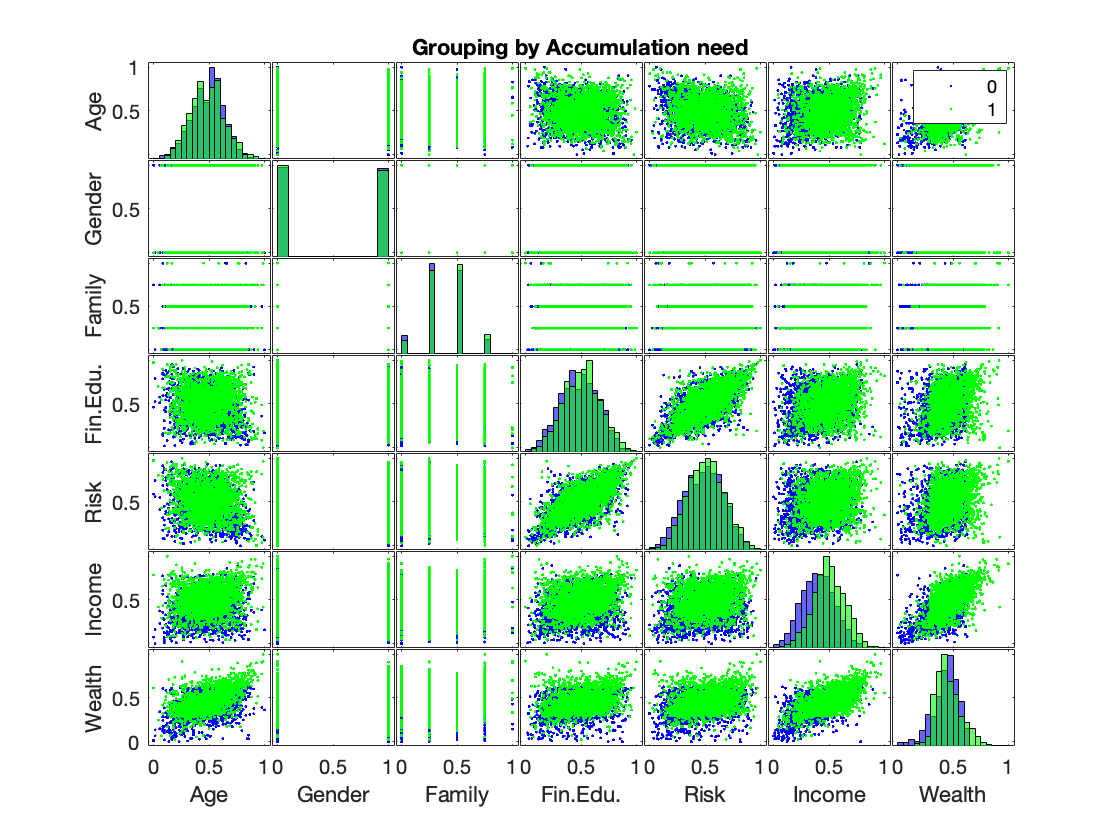

figure
xnames = {'Age','Gender', 'Family', 'Fin.Edu.', 'Risk', 'Income', 'Wealth'};
gplotmatrix(X,[],Data.AccumulationInvestment, [],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

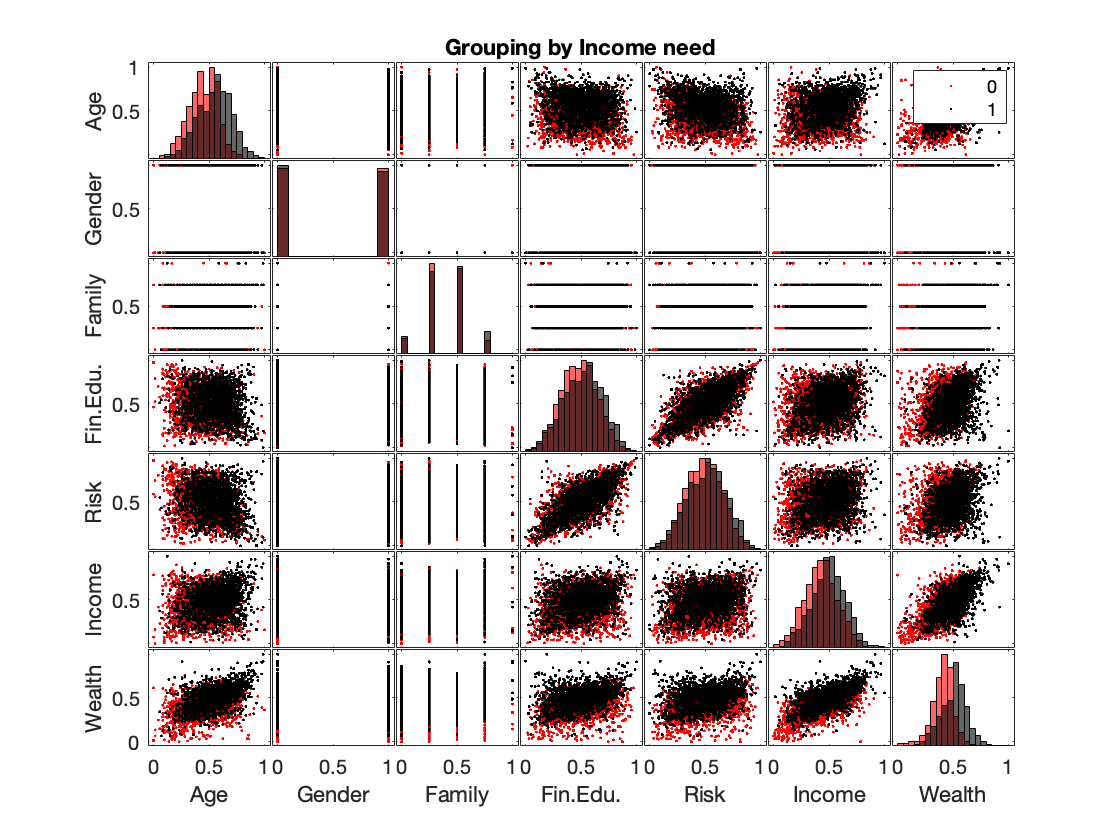

figure
xnames = {'Age','Gender', 'Family', 'Fin.Edu.', 'Risk', 'Income', 'Wealth'};
gplotmatrix(X,[],Data.IncomeInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')

## Estimating Financial Needs

### Finding a classifier

A reasonable idea to get quick results is:

- divide data in (1) train/crossvalidation sample (we we will use k-fold cross-validation), and (2) test sample;

- the proportion might be 70%-30%, or 80%-20%;

- use the classification learner app in order to quickly explore and assess different models, train them and cross-validate them on the dataset (1), fine-tuning hyperparameters in the k-fold cross validation process;

- test a super short-list of models on the (unseen, full out-of-sample) test-set (2).

It would be even better and safer from the "avoid overfitting" perspective:

- divide data in (1) train/crossvalidation sample (we we will use k-fold cross-validation), (2) pure cross-validation, and (3) test sample;

- the proportion might be 60%-20%-20%, or something similar;

- use the classification learner app on the dataset (1) in order to explore different models, train them

- choose a subset of models and use the cross-validation set (2) to fine tune hyperparameters (e.g. k in k-NN, or learning rates and regularization parameters in Neural Networks, etc);

- test a super-short-list of models on the (unseen, full out-of-sample) test-set (3).

### Dividing our data

For the sake of time scarcity/brevity (...here we are doing an exercise, and I'm just giving you a hint of a solution), I'll go for the first approach, but whenever is possible I strongly suggest and practice the second approach.

I partion data directly, splitting features and responses, but you might find useful this function, `cvpartition`, that defines random partitions on a data set: [https://it.mathworks.com/help/stats/cvpartition.html](https://it.mathworks.com/help/stats/cvpartition.html).

% nObs = size(Data, 1);
% idxPermutation = randperm(nObs);
% X = X(idxPermutation,:); % random permutation
% nObsTrain = round(0.75*nObs);
% 
% XTrain = X(1:nObsTrain,:);
% XTest = X(nObsTrain+1:end,:);
% 
% yInvIncTrain = Data.IncomeInvestment(1:nObsTrain);
% yInvIncTest = Data.IncomeInvestment(nObsTrain+1:end);
% 
% yInvAccTrain = Data.AccumulationInvestment(1:nObsTrain);
% yInvAccTest = Data.AccumulationInvestment(nObsTrain+1:end);
% 
% varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth'};
% 
% XTrainTable=table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4), XTrain(:,5), XTrain(:,6),XTrain(:,7), 'VariableNames',varNames);
% XTestTable=table(XTest(:,1), XTest(:,2), XTest(:,3), XTest(:,4), XTest(:,5), XTest(:,6),XTest(:,7), 'VariableNames',varNames);

# Version with cross validation

nObs = size(Data, 1);
rng(10)
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
train = 0.75;
cross = 0;

nObsTrain = round(train*nObs);
nObsCross = round(cross*nObs);

XTrain = X(1:nObsTrain,:);
XCross = X((nObsTrain+1):(nObsTrain+nObsCross), :);
XTest = X(nObsTrain+1+nObsCross:end,:);


%********* Aggiunta permutazione delle Y uguale a quella delle X ********
YInc = Data.IncomeInvestment;
YInc = YInc(idxPermutation);

yInvIncTrain = YInc(1:nObsTrain);
yInvIncCross = YInc((nObsTrain+1):(nObsTrain+nObsCross));
yInvIncTest = YInc(nObsTrain+nObsCross+1:end);

YAcc = Data.AccumulationInvestment;
YAcc = YAcc(idxPermutation);

yInvAccTrain = YAcc(1:nObsTrain);
yInvAccCross = YAcc((nObsTrain+1):(nObsTrain+nObsCross));
yInvAccTest = YAcc(nObsTrain+nObsCross+1:end);

varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth'};
XTrainTable=table(XTrain(:,1), XTrain(:,2), XTrain(:,3), XTrain(:,4), XTrain(:,5), XTrain(:,6),XTrain(:,7), 'VariableNames',varNames);
XTestTable=table(XTest(:,1), XTest(:,2), XTest(:,3), XTest(:,4), XTest(:,5), XTest(:,6),XTest(:,7), 'VariableNames',varNames);

### Using the classification learner

Most of the time you need quick results. So let's use the classification learner, speeding up the modeling process, as it (is not exceptional but) allows for rapid model training/validation, then it generates the code (see an example here: [https://it.mathworks.com/help/stats/code-generation-and-classification-learner-app.html).](https://it.mathworks.com/help/stats/code-generation-and-classification-learner-app.html).) If you need a tool for rapid prototyping, you might also try [https://www.dataiku.com/product/get-started/](https://www.dataiku.com/product/get-started/) (the free trial doesn't expire, and it's enough for doing some fast model/data understanding - it's especially good if you have a Mac).

**NOTE**: my suggestion is, when you are researching the model that will be best for the type of data use the fastest programming language or platform FOR YOU (R/SPSS, Matlab/Octave, Python, SAS, Stan, Julia, whatever you like/you are proficient in). If you want to build a large scale deployment of a learning algorithm, first do fast prototyping (incidentally Matlab is a great prototyping language). So you can sort of getting your learning algorithms working quickly. Only then spend your time re-implementing the algorithm in the production language. If you can get your learning algorithms to work more quickly in your preferred language, then you have huge overall time savings.

### Doing some feature engineering using domain knowledge

I try using some financial know-how to refine the process. It's ususally a very good idea, a key advantage.

In this case, following the financial advisory best practice, my idea is:

- accumulation investment products are mainly (though not only) intended for relatively young people, say workers, who have more income than accumulated wealth;

- the "income" investment products are mostly intended for a public that has already accumulated a wealth, and is often older (often they are retired);

- since the Y's derive from the behavior of financial advisors who hopefully follow this practice, an interesting variable is the ratio income / wealth ratio (eliminating the subjects with too low wealth, otherwise the ratio would explode, and besides that they are not too important in terms of business);

- in order to have a cleaner picture I try to eliminate family size and gender, which are perhaps not so decisive (in principle, from a financial advisory perspective they shouldn't be so important). Even risk propensity shouldn't be so important in order to estimate financial needs (it's important in order to choose the right risk level given the product).

*HINT*: try to engineer your features (maybe you can find a rationale for the number of family members, the gender, maybe it's linked to the client's life-cycle or whatever).

IncomeWealthRatio = zeros(nObs,1);
IncomeWealthRatio(Data.Wealth>10) = pIncome(Data.Wealth>10)./pWealth(Data.Wealth>10);
Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinancialEducation) pIncome pWealth];

figure
xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth'};
gplotmatrix(Xsmall,[],Data.IncomeInvestment, ["r", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')
figure
xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth'};
gplotmatrix(Xsmall,[],Data.AccumulationInvestment, ["c", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

Back to the classification learner to see what happens: we create a smaller data table.

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest = Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), 'VariableNames',xnames);

### Directly training and testing an ensemble model

After a first, quick model assessment using the classification learner app, we are back...we are going to create a predictive classification ensemble using my selection of predictors.

Let's say we want to cross-validate an ensemble of classification trees using:

- Bootstrap Aggregation - basically a Random Forest (see [https://it.mathworks.com/matlabcentral/answers/92525-where-can-i-find-more-information-about-breiman-s-random-forest-method-used-by-treebagger-in-stati#answer_101875](https://it.mathworks.com/matlabcentral/answers/92525-where-can-i-find-more-information-about-breiman-s-random-forest-method-used-by-treebagger-in-stati#answer_101875)), which worked well in the classification learner app;

- 5-fold cross-validation;

- Each tree should be split a maximum of 5 times using a decision tree template.

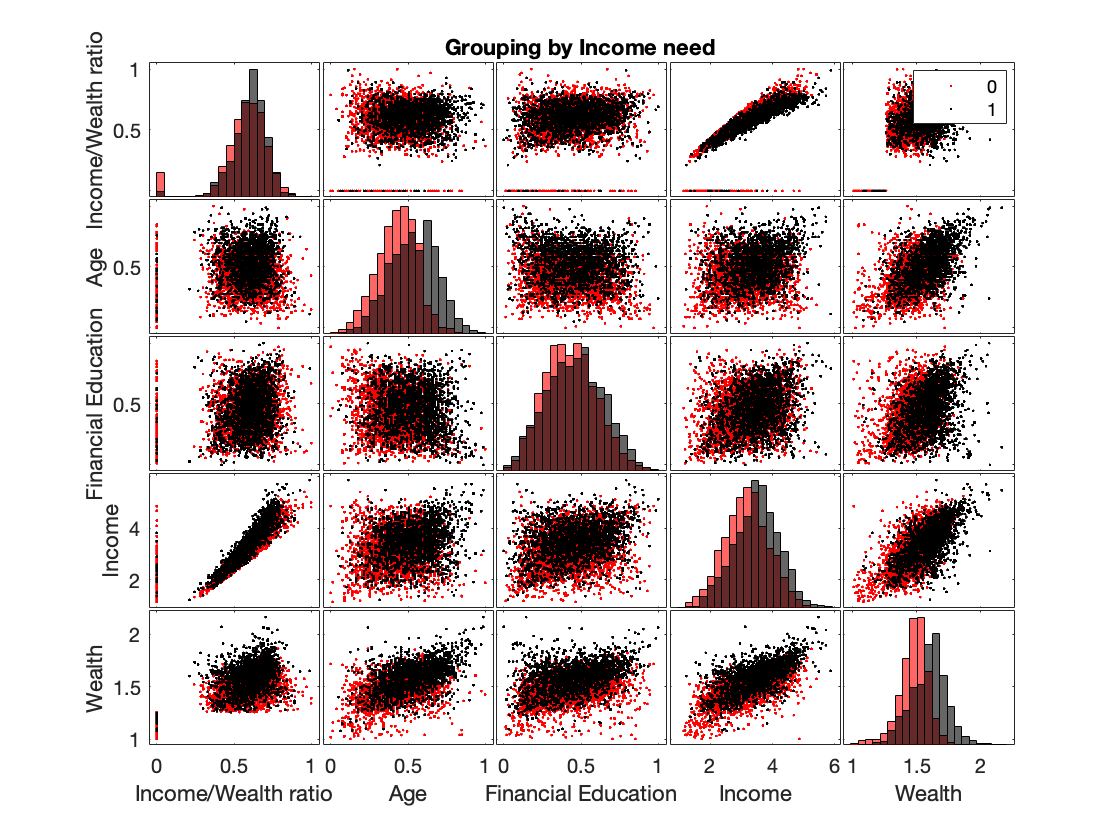

rng(5); % For reproducibility
% t = templateTree('MaxNumSplits',5);
t = templateTree();
% MdlBagging = fitcensemble(XsmallTrainTable,yInvAccTrain,'Method','Bag','Learners',t,'KFold',5,'CrossVal','on');

MdlBagging = fitcensemble(XTrainTable,yInvAccTrain,'Method','Bag','Learners',t,'KFold',5,'CrossVal','on');


Now we plot the cumulative misclassification rate, displaying the estimated generalization error of the ensemble. Plotting the cumulative loss allows you to monitor how the loss changes as weak learners accumulate in the ensemble.

CVLoss is the loss obtained by the cross-validated model (for every fold, `kfoldLoss` computes the loss).

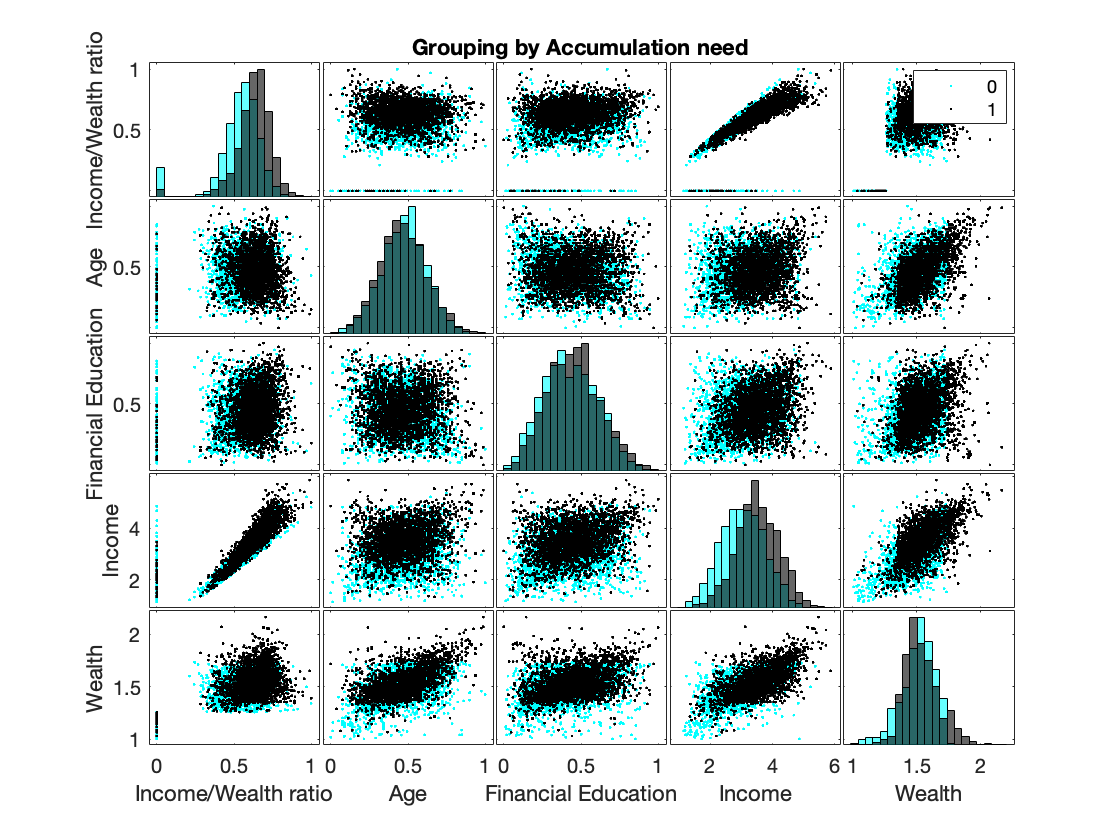

CVLoss = kfoldLoss(MdlBagging,'Mode','cumulative');
figure;

plot(CVLoss);
ylabel('10-fold Misclassification rate');
xlabel('Learning cycle');
estGenError = CVLoss(end)

The ensemble achieves a misclassification rate of 0.20-0.21 after accumulating about 20-40 weak learners. Then, the misclassification rate increases slightly as more weak learners enter the ensemble.

If you are satisfied with this misclassification rate error, then, create a predictive model training the ensemble again using all of the settings except cross-validation, i.e. MdlBagging = fitcensemble(XsmallTrainTable,yInvAccTrain,'Method','Bag','Learners',t,'CrossVal','off');

However, you should tune the hyperparameters, i.e.

- the maximum number of decision splits per tree;

- the number of learning cycles.

You cand do stuff like this manually, or you can using an algorithm that search the best solution for you...

### Finding & fitting "the best" ensemble

Let's fit an optimal ensemble of learners for classification: we automatically optimize ensemble hyperparameters using the function `fitcensemble.` It finds hyperparameters that minimize k-fold cross-validation loss (K=5 here, but you can change K) by using automatic hyperparameter optimization. As we  specify `'OptimizeHyperparameters'`, the function finds optimal parameters automatically using Bayesian optimization - see [https://it.mathworks.com/help/stats/bayesianoptimization.html](https://it.mathworks.com/help/stats/bayesianoptimization.html).

rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
% MdlOptimum = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
%     'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))
MdlOptimum = fitcensemble(XTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))


The optimization routine searched over the universe of ensemble aggregation methods for one-vs-all classification, over `NumLearningCycles`, `LearnRate` (if applicable), and `MinLeafSize` - see here the ensemble learning algorithms supported by Matlab: [https://it.mathworks.com/help/stats/ensemble-algorithms.html?s_tid=srchtitle_ensemble_1](https://it.mathworks.com/help/stats/ensemble-algorithms.html?s_tid=srchtitle_ensemble_1). 

(If you wonder about XGboost - which is not an algorithm, but jus an implementation - in Matlab, you have a number of options: [https://it.mathworks.com/support/search.html/answers/457195-what-functionality-does-matlab-offer-for-gradient-boosting-that-is-equivalent-to-xgboost.html?fq=asset_type_name:answer%20category:stats/classification-ensembles&page=1](https://it.mathworks.com/support/search.html/answers/457195-what-functionality-does-matlab-offer-for-gradient-boosting-that-is-equivalent-to-xgboost.html?fq=asset_type_name:answer%20category:stats/classification-ensembles&page=1)).

**The output MdlOptimum is the ensemble classifier with the minimum estimated cross-validation loss**.

### Explaining results

If you cannot use inherently interpretable classification models, such as linear models, decision trees, and generalized additive models, then use interpretability features to interpret complex, black box classification models (Boosting, Bagging, Neural Networks) that usually work well but are not inherently interpretable.

There are a number of methods, such as:

LIME - interpret a prediction for a query point by fitting a simple interpretable model (eg a linear model, or a simple tree) for the query point; this simple model acts as an approximation for the trained model and explains model predictions around the query point.

SHAP - it is an astute application of Game Theory. The Shapley value of a feature for a given query point explains the contribution of the feature to a prediction at the specified query point. The Shapley value corresponds to the deviation of the prediction for the query point from the average prediction, due to the feature (note: for each query point, the sum of the Shapley values for all features = total deviation of the prediction from the average).

The latter is state-of-the-art, and very pop.

row = 3; % query point, ie a specific example = customer
queryPoint = XsmallTrainTable(row,:)
explainer = shapley(MdlOptimum,'QueryPoint',queryPoint)
plot(explainer)

*HINTS*: you shoild might try different models, for example black-box models like Neural Networks of different size and structure, various Ensembles, and so on, AND more baseline, much more transparent models like Naive Bayes and Logistic regression, etc. There is a vast number of models available in Matlab: [https://it.mathworks.com/help/stats/classification.html?s_tid=CRUX_topnav](https://it.mathworks.com/help/stats/classification.html?s_tid=CRUX_topnav)

You might also try to interpret models, see [https://it.mathworks.com/help/stats/interpretability-classification.html?s_tid=CRUX_lftnav](https://it.mathworks.com/help/stats/interpretability-classification.html?s_tid=CRUX_lftnav) 

## Prediction

Using MDLOptimum, our best ensemble classifier, we get:

- predicted labels (i.e., Ys);

- scores (the confidence that an observation originates from a specific class; the higher the score, the higher the confidence; note that different ensemble algorithms have different definitions for their scores: `Bag` scores range from `0` to `1,AdaBoostM1`, `GentleBoost`, `LogitBoost` scores range from -inf to +inf).

We can examine scores (which are essentially probabilities averaged over all the trees in the ensemble) in order to understand how strong is the model conviction.

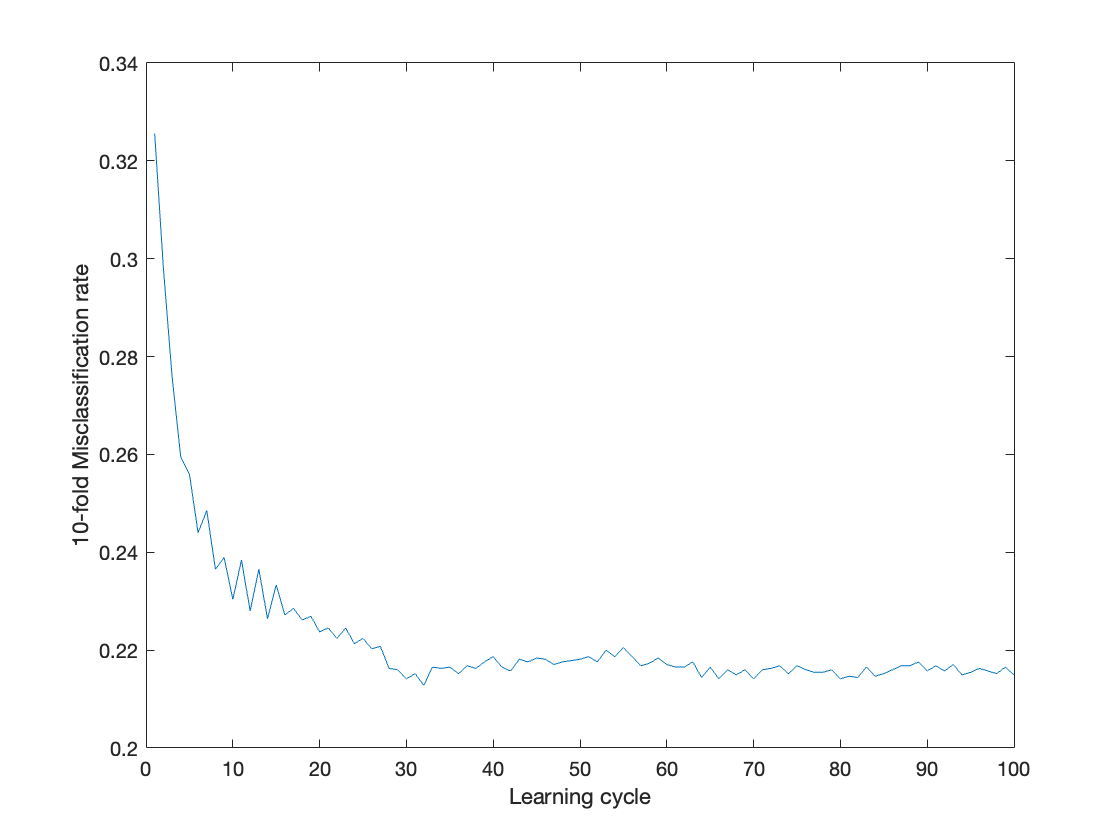

[labels,scores] = predict(MdlOptimum,XsmallTest);

figure
histogram(max(scores')')
title('ArgMax[scores = pseudo-probabilities]')

xlabel('Score')

estGenError = 0.2149

ylabel('Absolute frequency')

Let's compute **Precision**, **Recall**, and the **F1 score**, which tells you how well you're doing on finding the ground truth, computing how many examples the current threshold classifies correctly and incorrectly.

Memento. The F1 score is computed using Precision and Recall:

,

Precision and recall are given by:

where

- tp is the number of true positives: the ground truth label says it's 1 and our algorithm correctly classified it as 1.

- fp is the number of false positives: the ground truth label says it's 0, but our algorithm incorrectly classified it as 1.

- fn is the number of false negatives: the ground truth label says it's 1, but our algorithm incorrectly classified it as 0.

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      0.3096 |      3.8951 |      0.3096 |      0.3096 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |     0.21093 |      4.5496 |     0.21093 |     0.21656 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Accept |     0.21093 |     0.96837 |     0.21093 |     0.21364 |          Bag |           12 |            - |           18 |
|    4 | Accept |     0.37093 |     0.88899 |     0.21093 |   

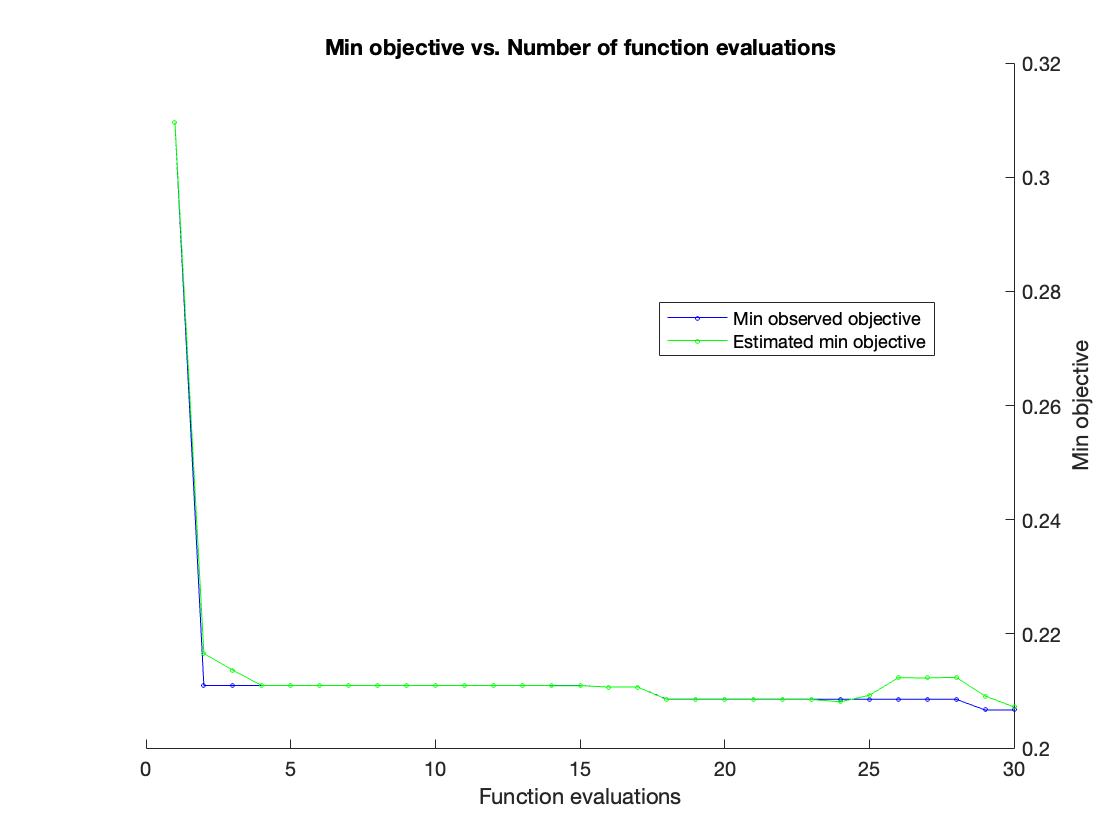


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 240.5644 seconds
Total objective function evaluation time: 216.5752

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             487              NaN            8     

Observed objective function value = 0.20667
Estimated objective function value = 0.20823
Function evaluation time = 36.2285

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MdlOptimum =   ClassificationBaggedEnsemble
                       PredictorNames: {'Age'  'Gender'  'Family'  'FinEdu'  'Risk'  'Income'  'Wealth'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 482
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     UseObsForLearner: [3750×482 l

tp = sum((labels == '1') & (yInvAccTest=='1'));
fp = sum((labels == '1') & (yInvAccTest=='0'));
fn = sum((labels == '0') & (yInvAccTest=='1'));
prec = tp / (tp + fp)
rec = tp / (tp + fn)
F1 = 2 * prec * rec / (prec + rec)

**IMPORTANT NOTE**: when you use scaled or normalized features, it is important that you **scale/normalize all the data in the same way, using the same parameters**, otherwise the model will not work properly. This means that, for example:

- if you use a z-score, you should store mu and sigma for each feature[`[Z,mu,sigma] = zscore(``___``)`](https://it.mathworks.com/help/releases/R2021a/stats/zscore.html?s_tid=doc_ta#d123e851945)`;`

- if you use min/max rescaling, you should compute and store the min/max for each feature (so if X is the matrix with all the features, you must compute and store the two vectors `colmin = min(X), colmax = max(X)`);

- **when you need to make a prediction with new data, you first have to rescaling the input using the same parameters as above**, that is mu and sigma, or colmin and colmax.

## Next Best Action: recommending products

Now we generate the personalized recommendation for the Accumulation products, that is, Products.Type==1.

Here I adopt the following rules, for each client:

- **matching product type and client need (predicted using the ensemble model)**;

- **matching product risk and client risk**;

- **suggesting one single product** - alternatively we might suggest **a list of products**, ranked based on their fit to each client profile (the first approach, being "straight", would be preferable for a robo-advisory service or a sales network that needs a lot of support, the latter is more suitable for a network of expert financial consultants who just need a little decision support).

For simplicity and to continue the example, we do that for the clients in the test set (but the rules work for an arbitrary set of clients).

### Retrieving data

Retrieving IDs and risk propensities for the client in the test set, and products (using the variable idxPermutation).

% Retrieving clients IDs
ClientID = Data.ID(idxPermutation);
ClientIDTest = ClientID(nObsTrain+1:end,:);

Unrecognized function or variable 'XsmallTrainTable'.

TargetClientID = ClientIDTest(labels=='1');

% Retrieving clients' risk propensities
ClientRiskPropensity = Data.RiskPropensity(idxPermutation);
ClientRiskPropensityTest = ClientRiskPropensity(nObsTrain+1:end,:);
TargetClientRiskPropensity = ClientRiskPropensityTest(labels=='1');

% Let's have a look at these risk propensities...
figure
histogram(ClientRiskPropensityTest, 'FaceColor', 'r')
title('Risk Propensity of target clients')
xlabel('Risk propensity')
ylabel('Frequency')
AccumulationProducts = Products(Products.Type == 1,:)

### Creating the personalized recommandations:

- The suitable products are those with a risk level below the client risk tolerance;

- Among those products, we select the one with the highest risk level (sure, we might do otherwise, it depends on the situation).

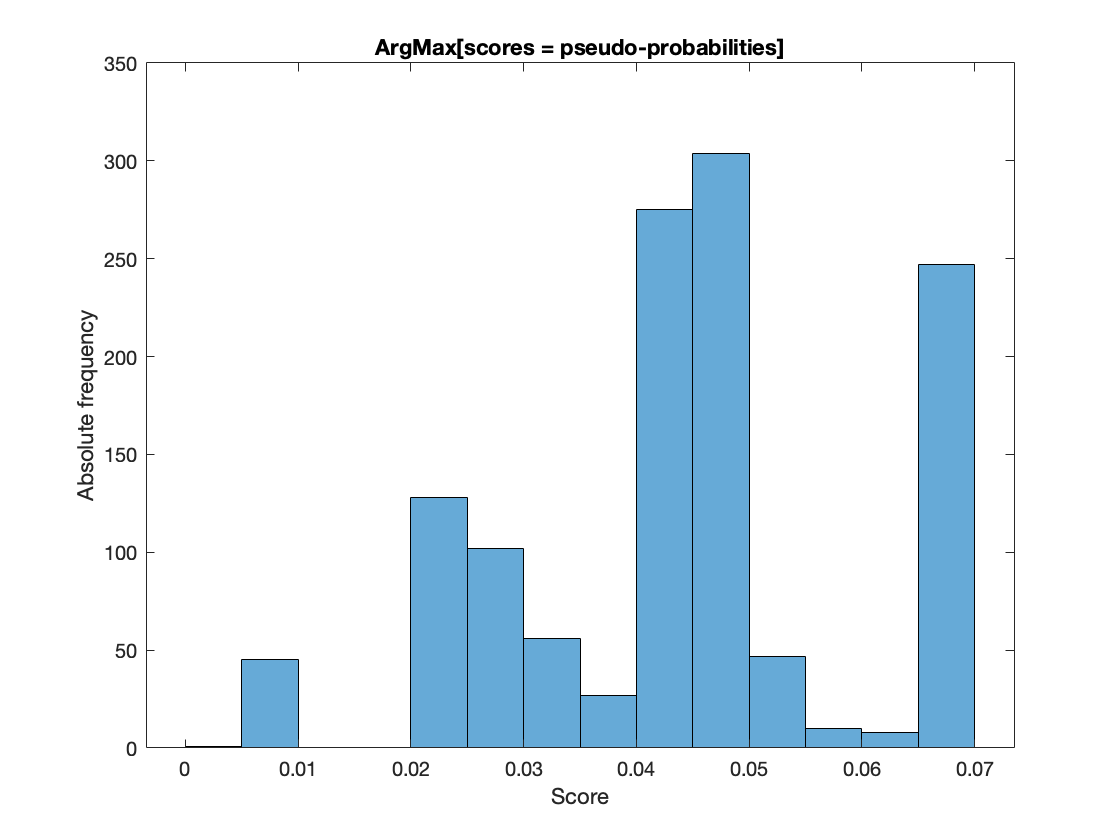

NBA_IDProduct = [];
RecommendedRiskLevel = [];
minRisk = min(AccumulationProducts.Risk);

product_ID =cast(AccumulationProducts.ID, "uint16");
client_ID = cast(TargetClientID, "uint16");

for i = 1: size(TargetClientRiskPropensity, 1)
    if TargetClientRiskPropensity(i)> minRisk
        % find the suitable product with the highest acceptable risk
        M = max(AccumulationProducts.Risk(AccumulationProducts.Risk<TargetClientRiskPropensity(i)));
        NBA_IDProduct = [NBA_IDProduct; product_ID(AccumulationProducts.Risk == M)];
    else
        % no suitable product in the product range
        NBA_IDProduct = [NBA_IDProduct; 0];
        M = 0;

prec = 0.4900

    end

rec = 0.6609

    RecommendedRiskLevel = [RecommendedRiskLevel; M];

F1 = 0.5628

end

% recommendations
NBA = [client_ID NBA_IDProduct];

figure
c = linspace(0,1,length(TargetClientRiskPropensity));
scatter(TargetClientRiskPropensity, RecommendedRiskLevel, [], c, 'filled')
title('Adequacy: client risk propensity vs product risk')
xlabel('Client risk propensity')
ylabel('Product risk')

## What can you do next

You can do many things, for example:

- Classify clients based on both needs, as I used just one single need, thus concluding this work;

- Try different models (multi-class?), and compare them (maybe looking at bias, variance, etc);

- Try different feature selection/engineering methods, both domain-based, and algorithmic;

- Try to imagine different recommendation rules/systems;

- Try explaining models,

- (...creativity is your limit...)

TF = ismissing(XTestTable,{'' '.' 'NA' NaN -99});
rowsWithMissing = XTestTable(any(TF,2),:);
disp(rowsWithMissing)





yPred = trainedModel.predictFcn(XTestTable);
err = (sum(yPred~=yInvIncTest))/length(yInvAccTest)

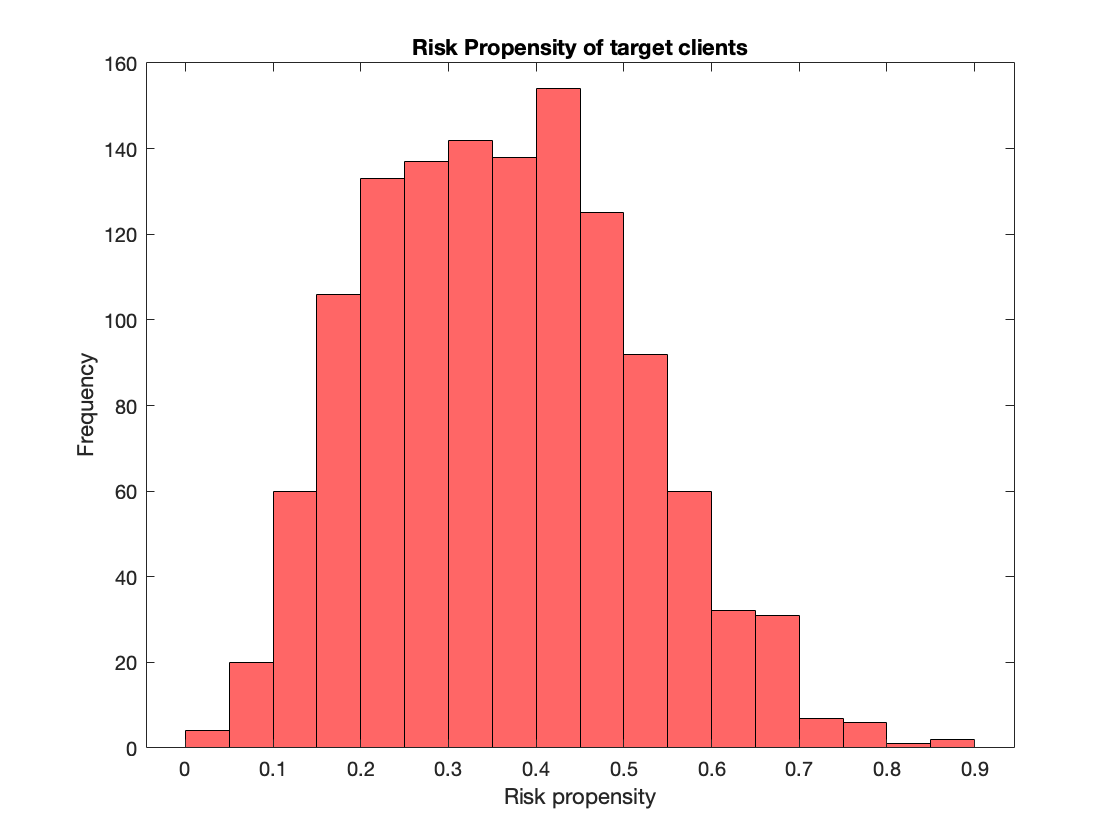

AccumulationProducts = 7×3 table
    ID    Type    Risk
    __    ____    ____

    1      1      0.55
    5      1      0.41
    6      1      0.36
    7      1      0.75
    8      1      0.48
    9      1      0.27
    11     1      0.88


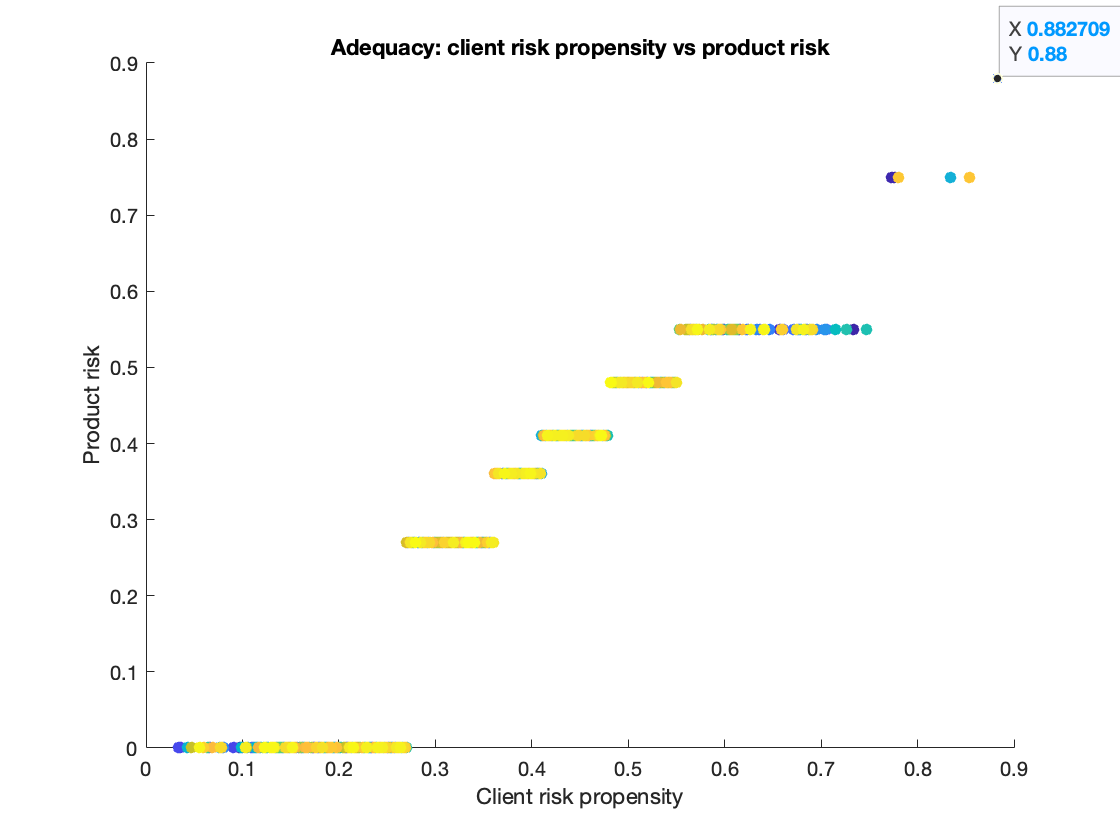

err = 0.2128

queryPoint = 1×7 table
      Age      Gender    Family    FinEdu      Risk      Income     Wealth 
    _______    ______    ______    _______    _______    _______    _______

    0.59995      1        0.25     0.72491    0.68406    0.57228    0.53498


explainer =   shapley with properties:

            BlackboxModel: [1×1 classreg.learning.classif.ClassificationBaggedEnsemble]
               QueryPoint: [1×7 table]
           BlackboxFitted: 1
            ShapleyValues: [7×3 table]
               NumSubsets: 128
                        X: [3750×7 table]
    CategoricalPredictors: []
                   Method: 'interventional-kernel'


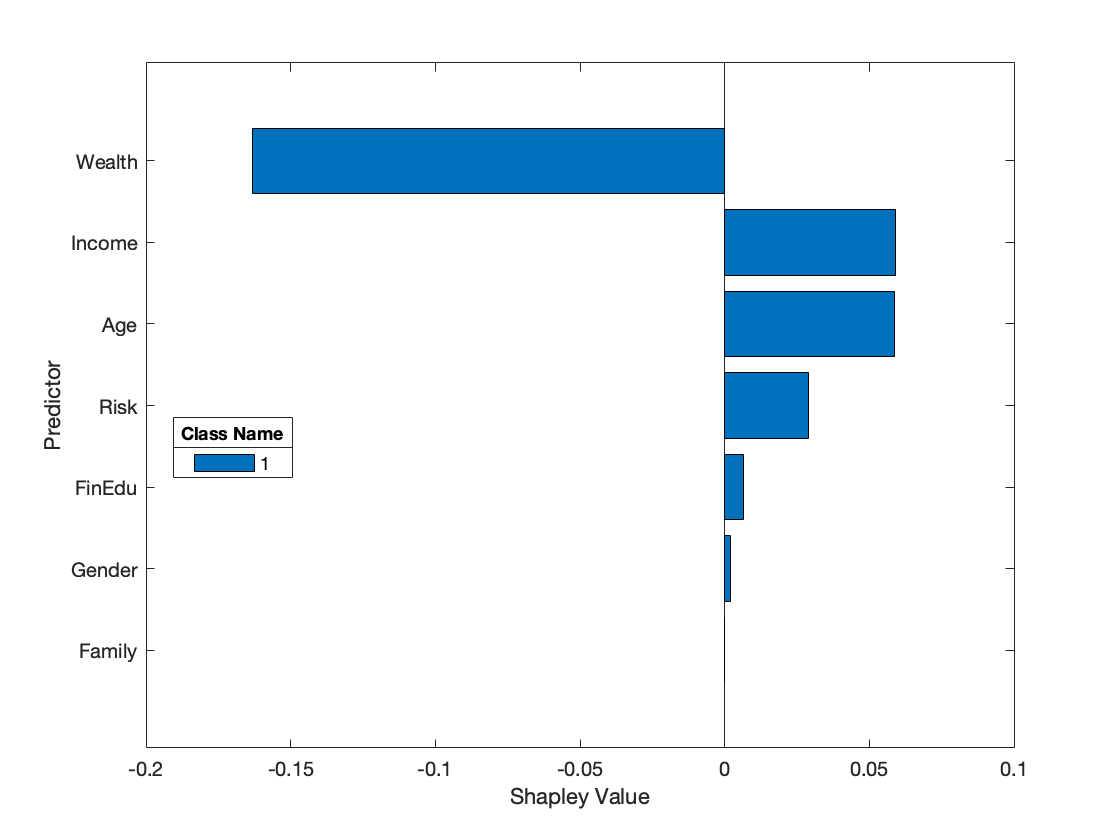

row = 123; % query point, ie a specific example = customer
queryPoint = XTrainTable(row,:)
explainer = shapley(MdlOptimum,'QueryPoint',queryPoint)
plot(explainer)